## starting figures

load("automated_out.mat")
load("LAB_Results\R01_pid_emulation.mat")

#### dd plot of 1ms step responses: left model, right lab data, all discritizations and also continuous time overlapped in one plot

load(R01)

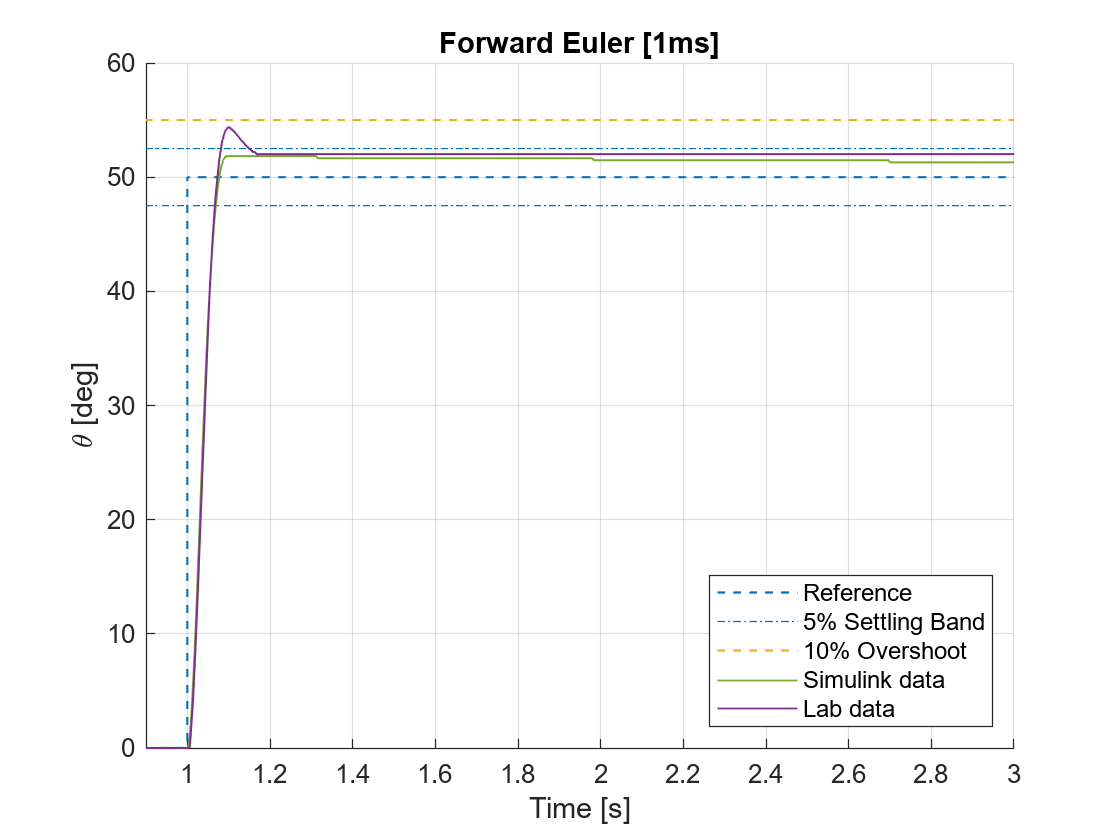

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.FE.T1.thl_meas.time, nominal_track.FE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.FE.T1.thl_meas.time, pid_nominal_track.FE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Forward Euler [1ms]')
axis([0.9 3 0 60])
exportgraphics(gcf,'Figures\01_PID_01\FE.pdf','ContentType','vector')

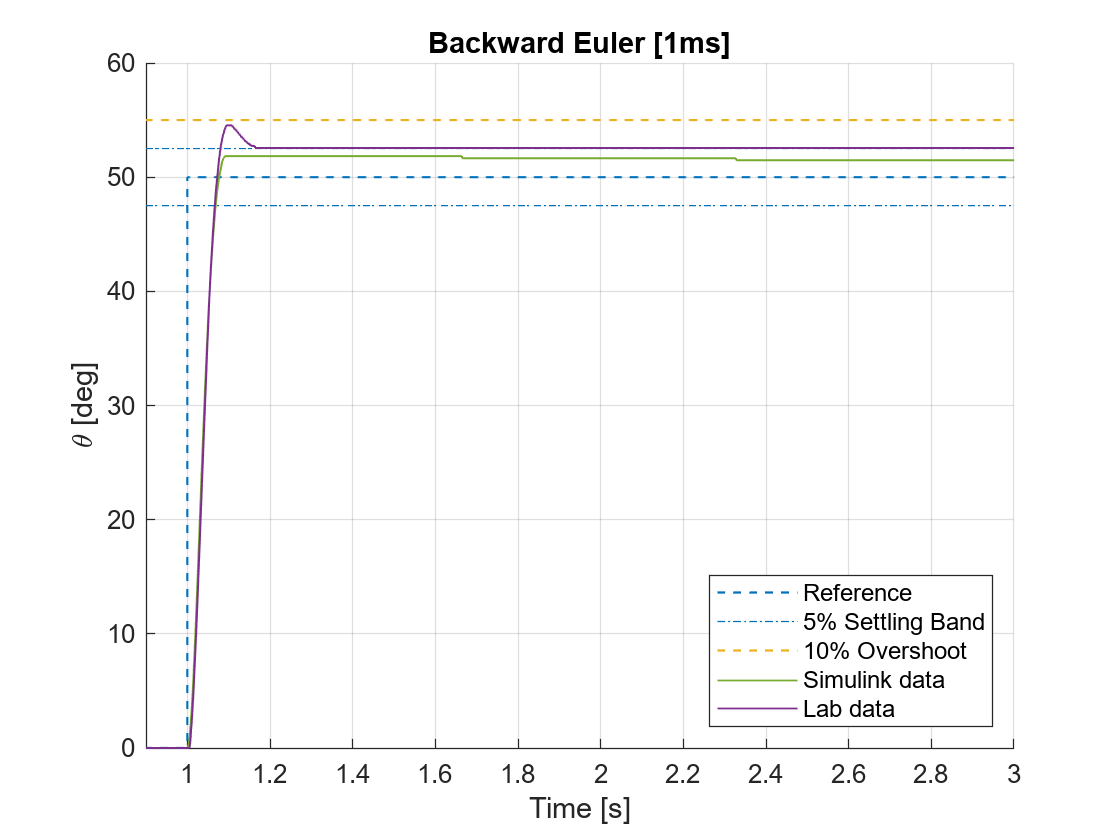

figure
hold on
% Ref
stairs(pid_nominal_track.BE.T1.thref.time, pid_nominal_track.BE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.BE.T1.thl_meas.time, nominal_track.BE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.BE.T1.thl_meas.time, pid_nominal_track.BE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Backward Euler [1ms]')
axis([0.9 3 0 60])
exportgraphics(gcf,'Figures\01_PID_01\BE.pdf','ContentType','vector')

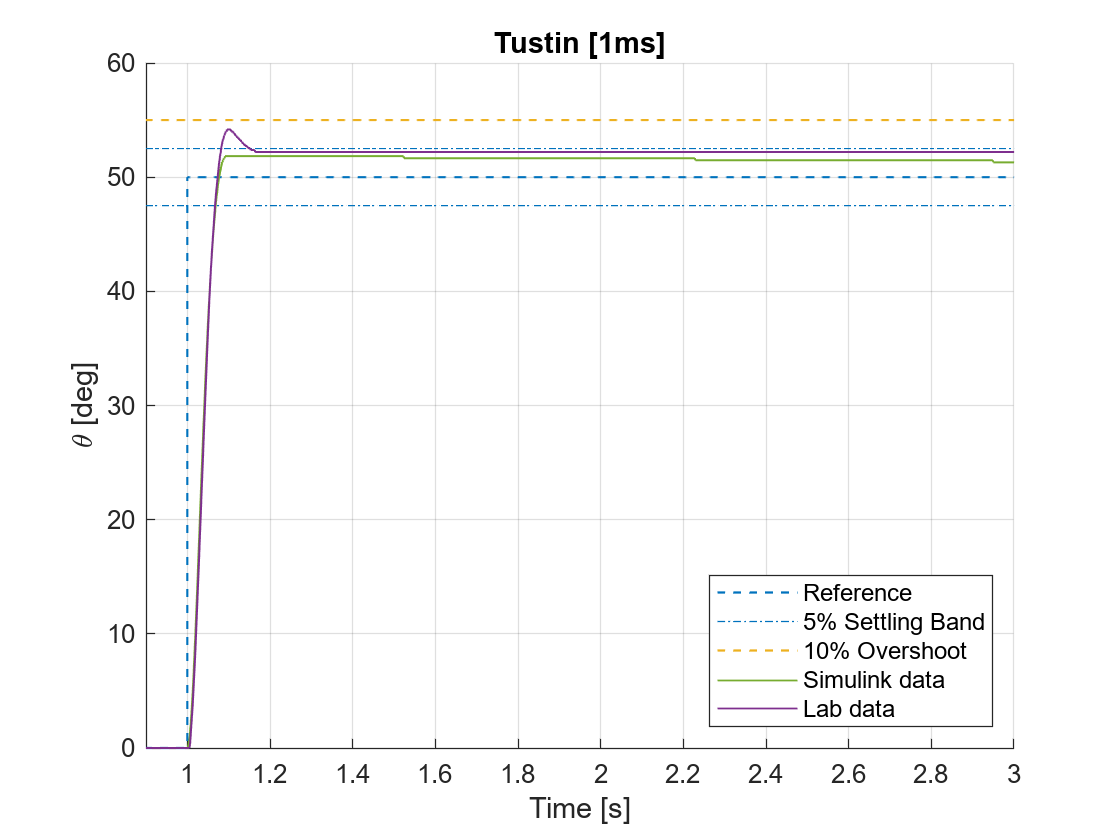

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.TU.T1.thl_meas.time, nominal_track.TU.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.TU.T1.thl_meas.time, pid_nominal_track.TU.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Tustin [1ms]')
axis([0.9 3 0 60])
exportgraphics(gcf,'Figures\01_PID_01\tustin.pdf','ContentType','vector')

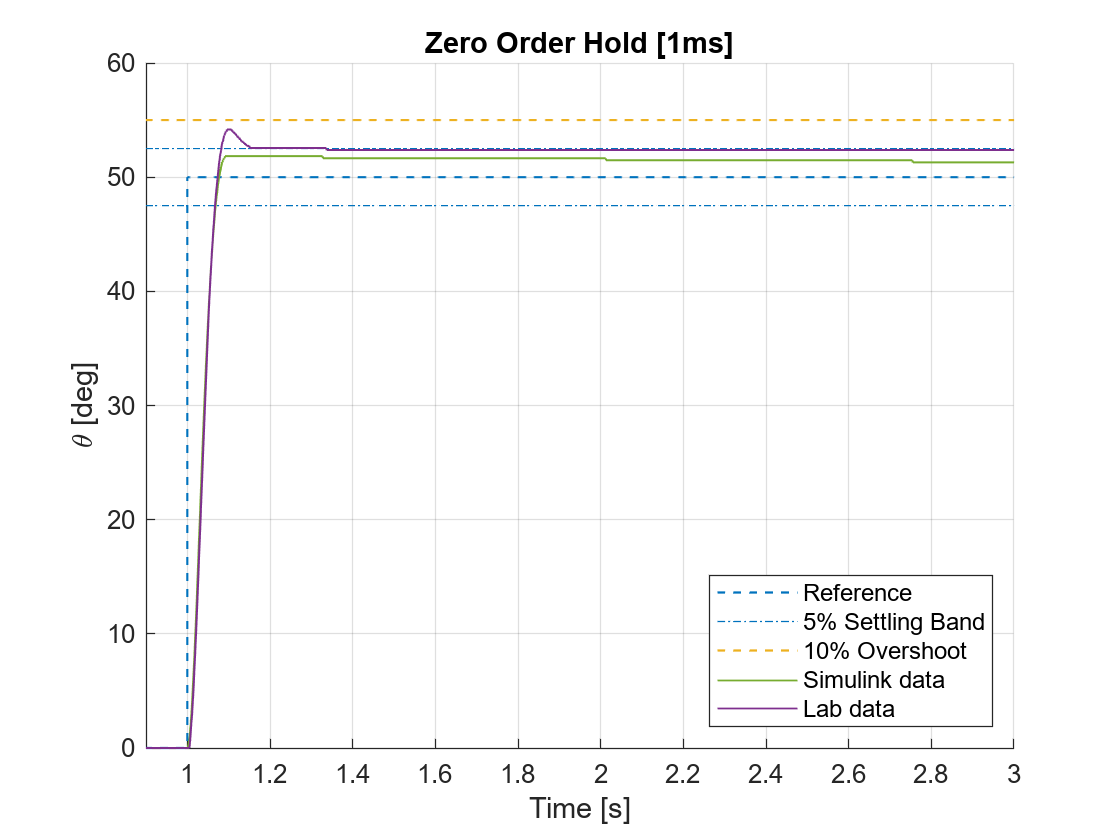

figure
hold on
% Ref
stairs(nominal_track.FE.T1.thref.time, nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T1.thref.time-1, nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.TU.T1.thl_meas.time, nominal_track.ZOH.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.ZOH.T1.thl_meas.time, pid_nominal_track.ZOH.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Zero Order Hold [1ms]')
axis([0.9 3 0 60])
exportgraphics(gcf,'Figures\01_PID_01\ZOH.pdf','ContentType','vector')

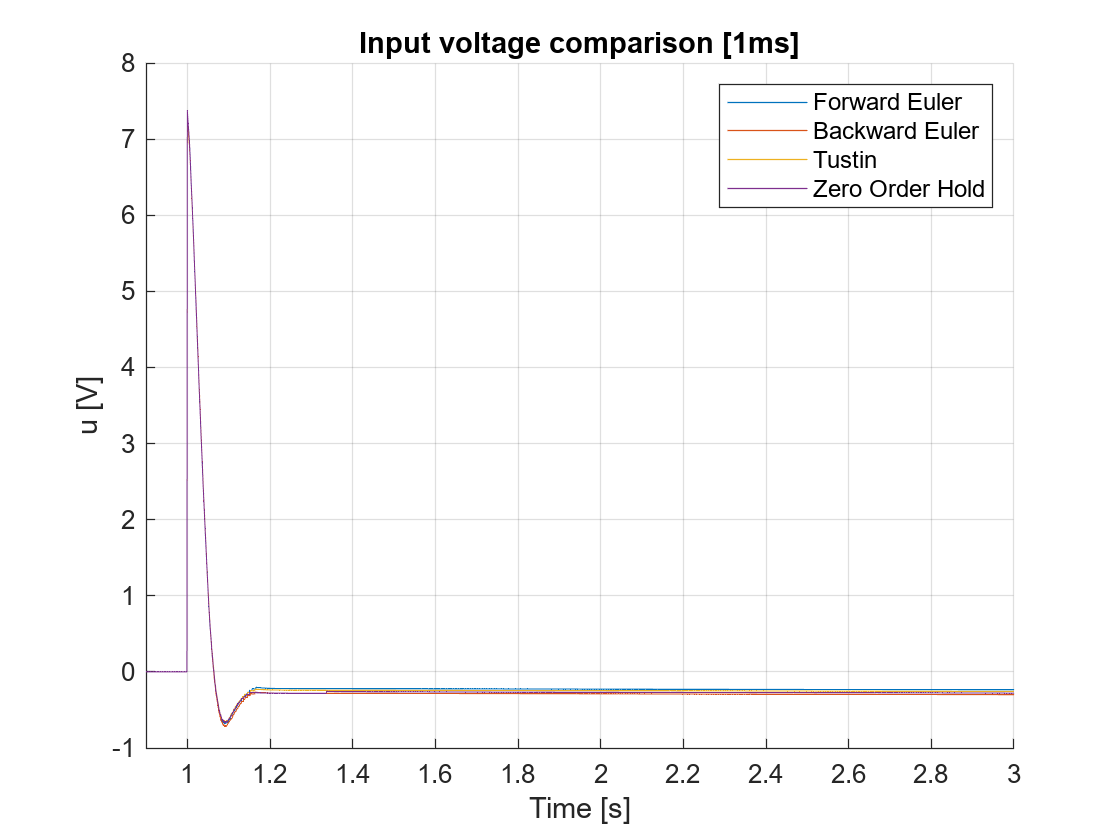

figure
hold on

plot(pid_nominal_track.FE.T1.thl_meas.time, pid_nominal_track.FE.T1.u.signals.values);
plot(pid_nominal_track.BE.T1.thl_meas.time, pid_nominal_track.BE.T1.u.signals.values);
plot(pid_nominal_track.TU.T1.thl_meas.time, pid_nominal_track.TU.T1.u.signals.values);
plot(pid_nominal_track.ZOH.T1.thl_meas.time, pid_nominal_track.ZOH.T1.u.signals.values);

legend('Forward Euler','Backward Euler','Tustin','Zero Order Hold','Location','northeast')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input voltage comparison [1ms]')
axis([0.9 3 -1 8])
exportgraphics(gcf,'Figures\01_PID_01\input_voltage.pdf','ContentType','vector')

#### zoh,FE in 2 plots beside each other, 50ms Lab data

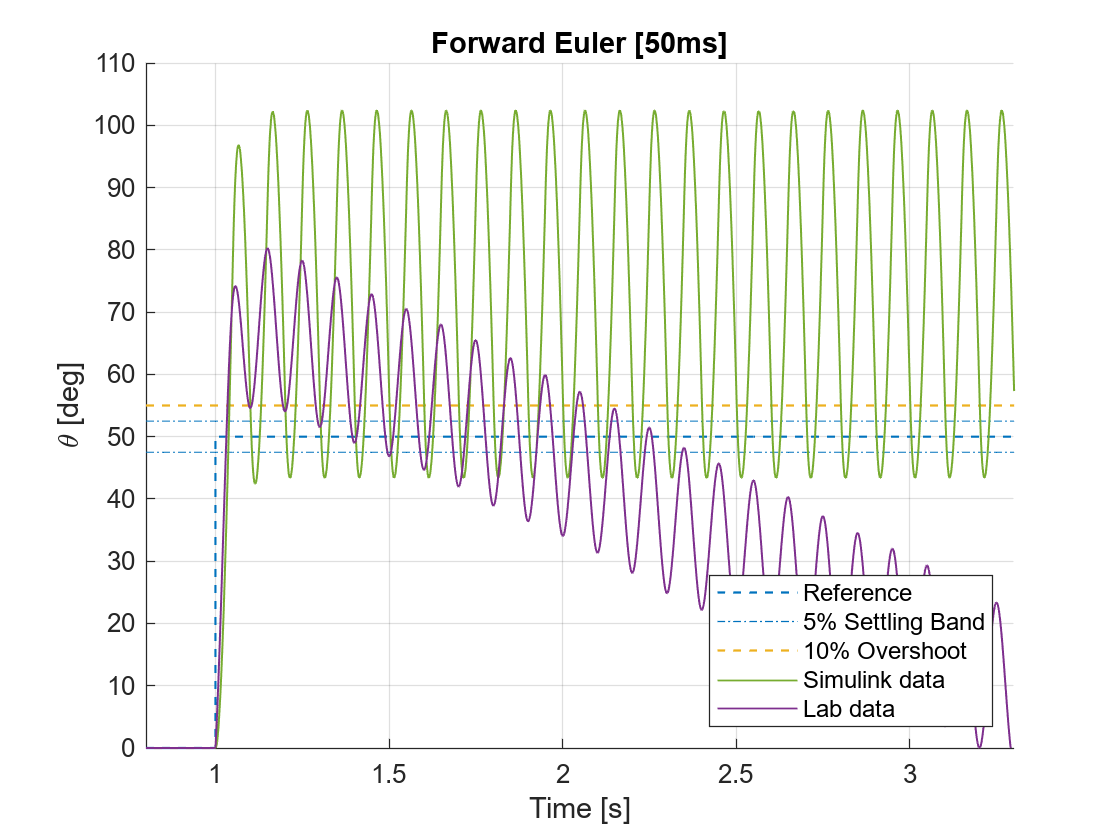

% Template to generate a figure
figure
hold on

% Ref
stairs(nominal_track.FE.T3.thref.time, nominal_track.FE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD" )
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.FE.T3.thref.time-1, nominal_track.FE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.FE.T3.thl_meas.time, nominal_track.FE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')

xx=linspace(pid_nominal_track.FE.T3.thl_meas.time(1),pid_nominal_track.FE.T3.thl_meas.time(end),5000);
yy=interp1(pid_nominal_track.FE.T3.thl_meas.time,pid_nominal_track.FE.T3.thl_meas.signals.values,xx,'spline');  
zero=zeros(1,500);
yy(1:500)=zero;

plot(xx, yy,'LineWidth',0.7,'Color', "#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot', 'Simulink data', 'Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Forward Euler [50ms]')
axis([0.8 3.3 0 110])
exportgraphics(gcf,'Figures\02_PID_50_FE_ZOH\FE.pdf','ContentType','vector')

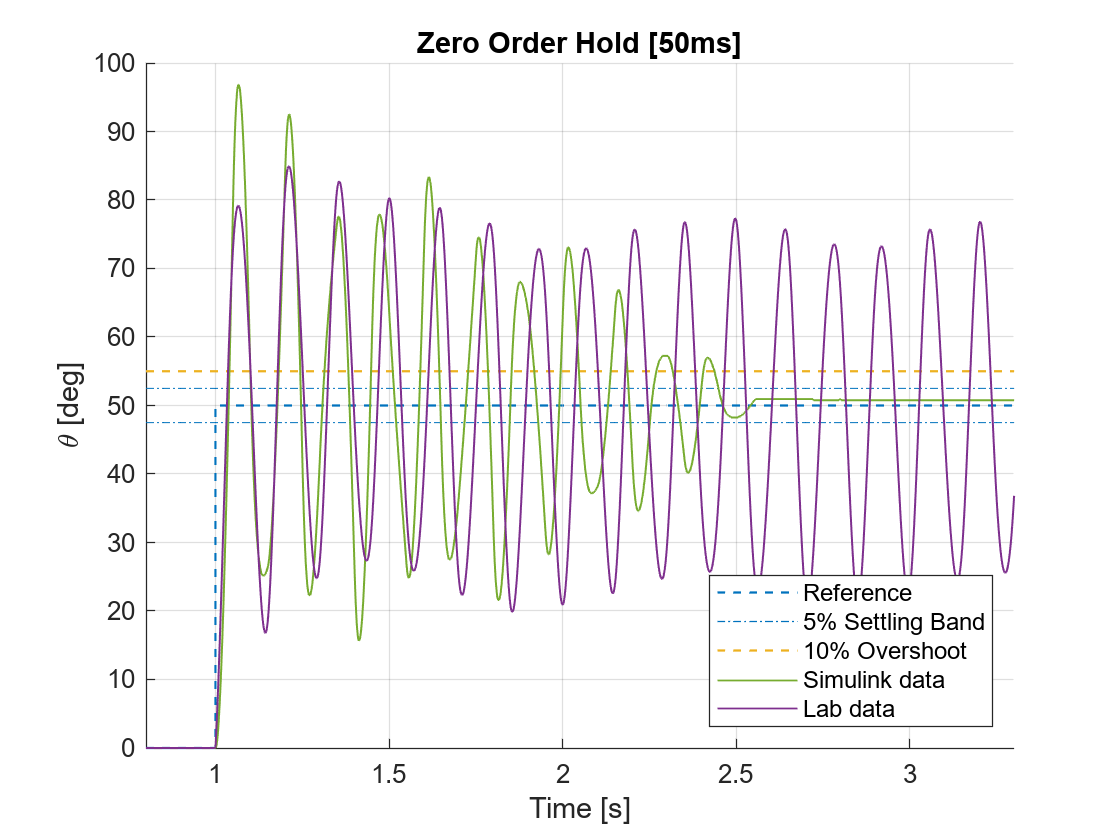

figure
hold on
% Ref
stairs(nominal_track.ZOH.T3.thref.time, nominal_track.ZOH.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*1.05,'-.','Color',"#0072BD" )
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.ZOH.T3.thref.time-1, nominal_track.ZOH.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.ZOH.T3.thl_meas.time, nominal_track.ZOH.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color',  '#77AC30')

xx=linspace(pid_nominal_track.ZOH.T3.thl_meas.time(1),pid_nominal_track.ZOH.T3.thl_meas.time(end),5000);
yy=interp1(pid_nominal_track.ZOH.T3.thl_meas.time,pid_nominal_track.ZOH.T3.thl_meas.signals.values,xx,'spline');  
zero=zeros(1,500);
yy(1:500)=zero;
plot(xx, yy,'LineWidth',0.7,'Color', "#7E2F8E")

% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')

grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Zero Order Hold [50ms]')
axis([0.8 3.3 0 100])
exportgraphics(gcf,'Figures\02_PID_50_FE_ZOH\ZOH.pdf','ContentType','vector')

#### 1 Plot - BE,tust,continous 50ms Lab data 

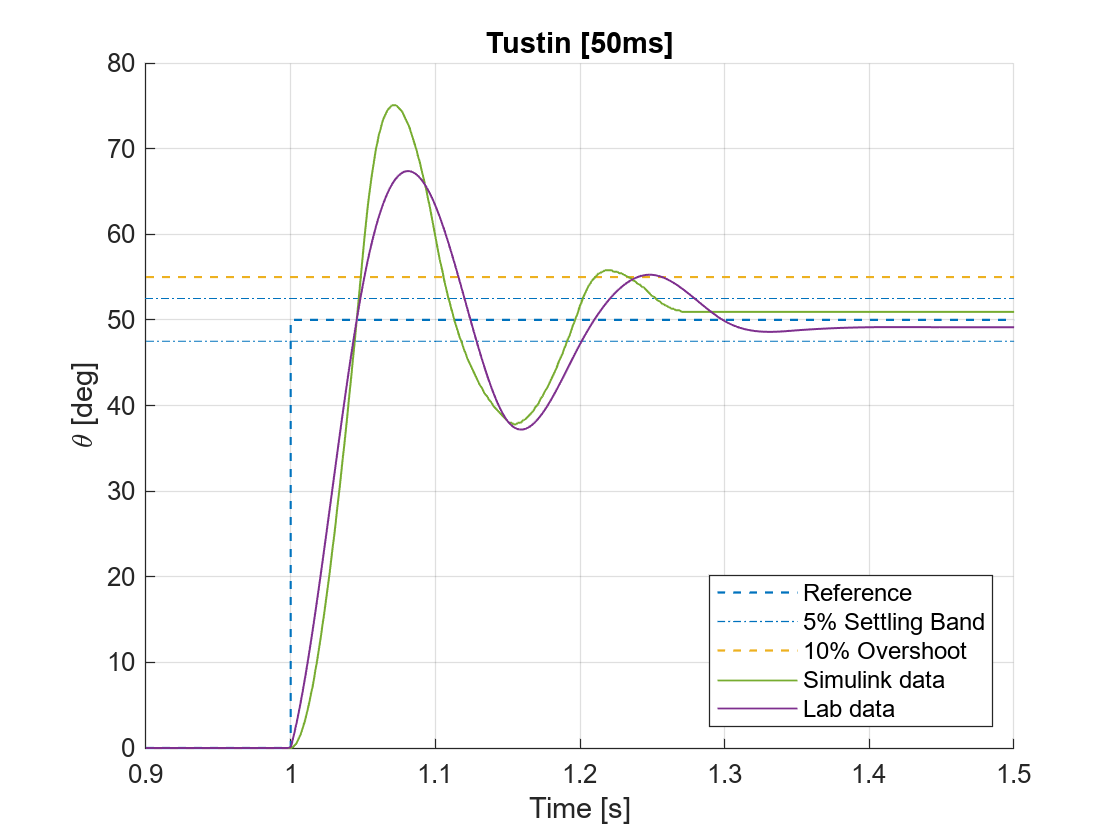

figure
hold on
% Ref
stairs(nominal_track.TU.T3.thref.time, nominal_track.TU.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.TU.T3.thref.time-1, nominal_track.TU.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.TU.T3.thref.time-1, nominal_track.TU.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.TU.T3.thref.time-1, nominal_track.TU.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

xx=linspace(pid_nominal_track.TU.T3.thl_meas.time(1),pid_nominal_track.TU.T3.thl_meas.time(end),5000);
yy=interp1(pid_nominal_track.TU.T3.thl_meas.time,pid_nominal_track.TU.T3.thl_meas.signals.values,xx,'spline');  
zero=zeros(1,500);
yy(1:500)=zero;



% Data
plot(nominal_track.TU.T3.thl_meas.time, nominal_track.TU.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
%plot(pid_nominal_track.TU.T3.thl_meas.time, pid_nominal_track.TU.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
plot(xx, yy,'LineWidth',0.7,'Color', "#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Tustin [50ms]')
axis([0.9 1.5 0 80])
exportgraphics(gcf,'Figures\03_PID_50_TU_BE\tustin.pdf','ContentType','vector')

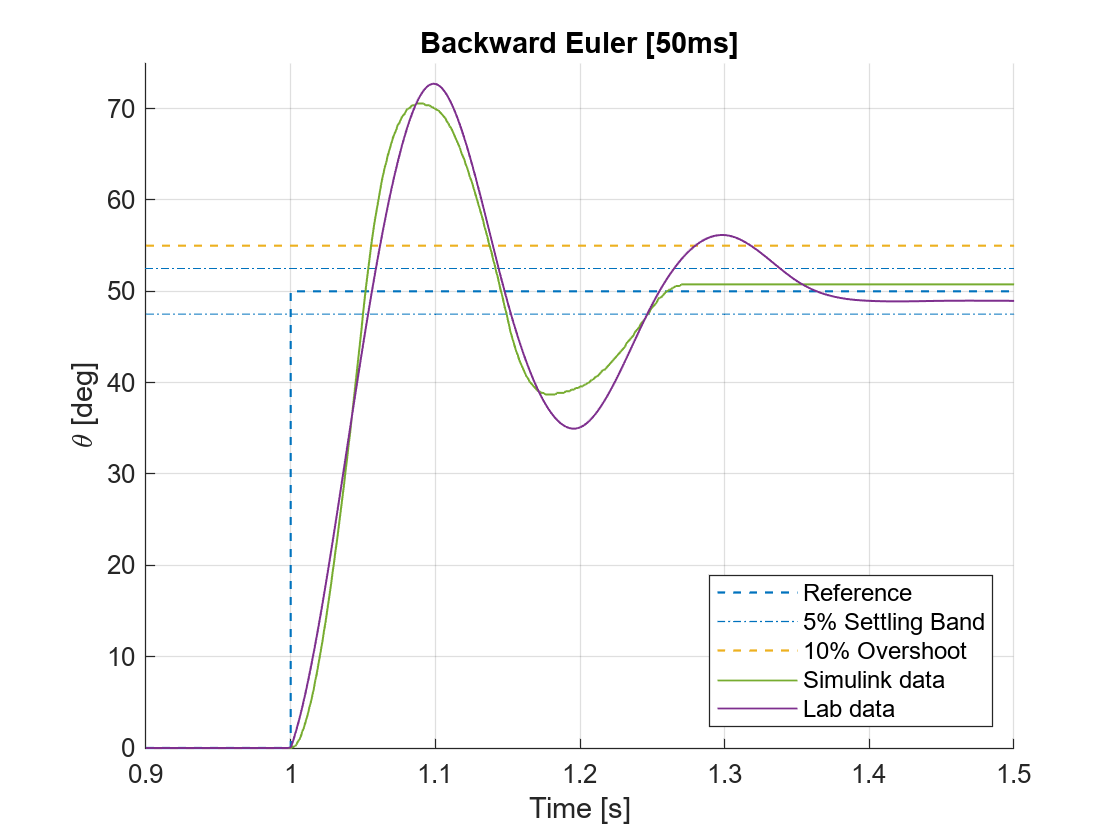


figure
hold on
% Ref
stairs(nominal_track.BE.T3.thref.time, nominal_track.BE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(nominal_track.BE.T3.thref.time-1, nominal_track.BE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(nominal_track.BE.T3.thref.time-1, nominal_track.BE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(nominal_track.BE.T3.thref.time-1, nominal_track.BE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)


xx=linspace(pid_nominal_track.BE.T3.thl_meas.time(1),pid_nominal_track.BE.T3.thl_meas.time(end),5000);
yy=interp1(pid_nominal_track.BE.T3.thl_meas.time,pid_nominal_track.BE.T3.thl_meas.signals.values,xx,'spline');  
zero=zeros(1,500);
yy(1:500)=zero;

% Data
plot(nominal_track.BE.T3.thl_meas.time, nominal_track.BE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
%plot(pid_nominal_track.BE.T3.thl_meas.time, pid_nominal_track.BE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
plot(xx, yy,'LineWidth',0.7,'Color', "#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Backward Euler [50ms]')
axis([0.9 1.5 0 75])
exportgraphics(gcf,'Figures\03_PID_50_TU_BE\BE.pdf','ContentType','vector')

1 no awu, CT(BB) and BE (Lab data) 10 ms

1 awu, CT (BB) and BE (Lab data) 10 ms

load("LAB_Results\R02_pid_awu.mat")

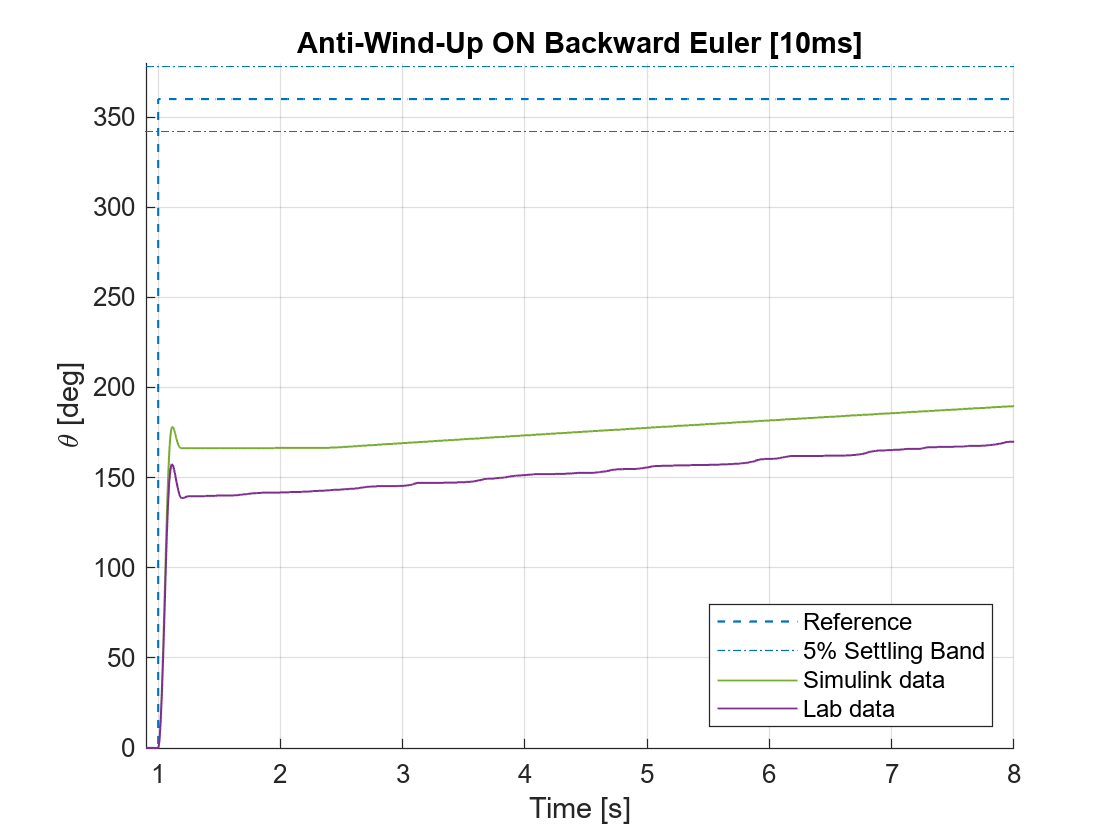

figure
hold on
% Ref
stairs(pid_nominal_track.AWU.BE.thref.time, pid_nominal_track.AWU.BE.thref.signals.values,'--','LineWidth',0.8)
plot(pid_nominal_track.AWU.BE.thref.time-1, pid_nominal_track.AWU.BE.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(pid_nominal_track.AWU.BE.thref.time-1, pid_nominal_track.AWU.BE.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(pid_nominal_track.AWU.BE.thref.time-1, pid_nominal_track.AWU.BE.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.AWU.BE.thl_meas.time, nominal_track.AWU.BE.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.AWU.BE.thl_meas.time, pid_nominal_track.AWU.BE.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-Wind-Up ON Backward Euler [10ms]')
axis([0.9 8 0 380])
exportgraphics(gcf,'Figures\04_PID_AWU\awu_BE.pdf','ContentType','vector')

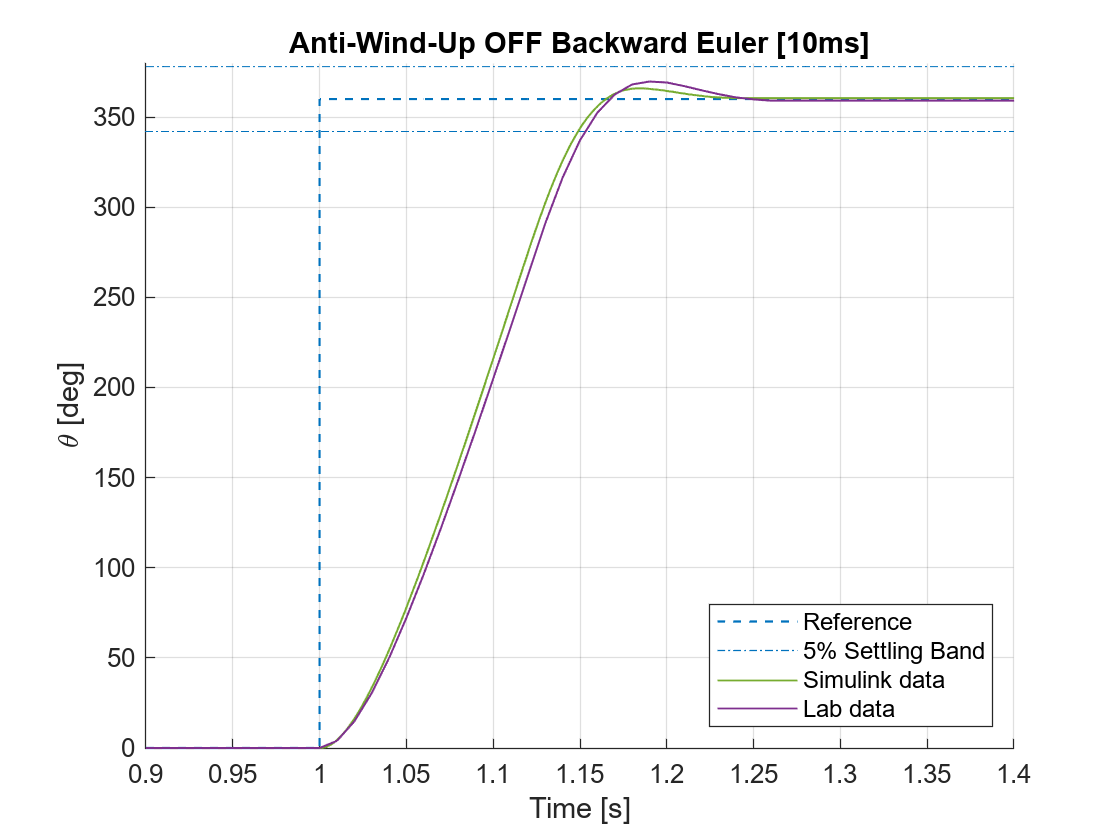

figure
hold on
% Ref
stairs(pid_nominal_track.NOAWU.BE.thref.time, pid_nominal_track.NOAWU.BE.thref.signals.values,'--','LineWidth',0.8)
plot(pid_nominal_track.NOAWU.BE.thref.time-1, pid_nominal_track.NOAWU.BE.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(pid_nominal_track.NOAWU.BE.thref.time-1, pid_nominal_track.NOAWU.BE.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(pid_nominal_track.NOAWU.BE.thref.time-1, pid_nominal_track.NOAWU.BE.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(nominal_track.NOAWU.BE.thl_meas.time, nominal_track.NOAWU.BE.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(pid_nominal_track.NOAWU.BE.thl_meas.time, pid_nominal_track.NOAWU.BE.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Anti-Wind-Up OFF Backward Euler [10ms]')
axis([0.9 1.4 0 380])
exportgraphics(gcf,'Figures\04_PID_AWU\no_awu_BE.pdf','ContentType','vector')

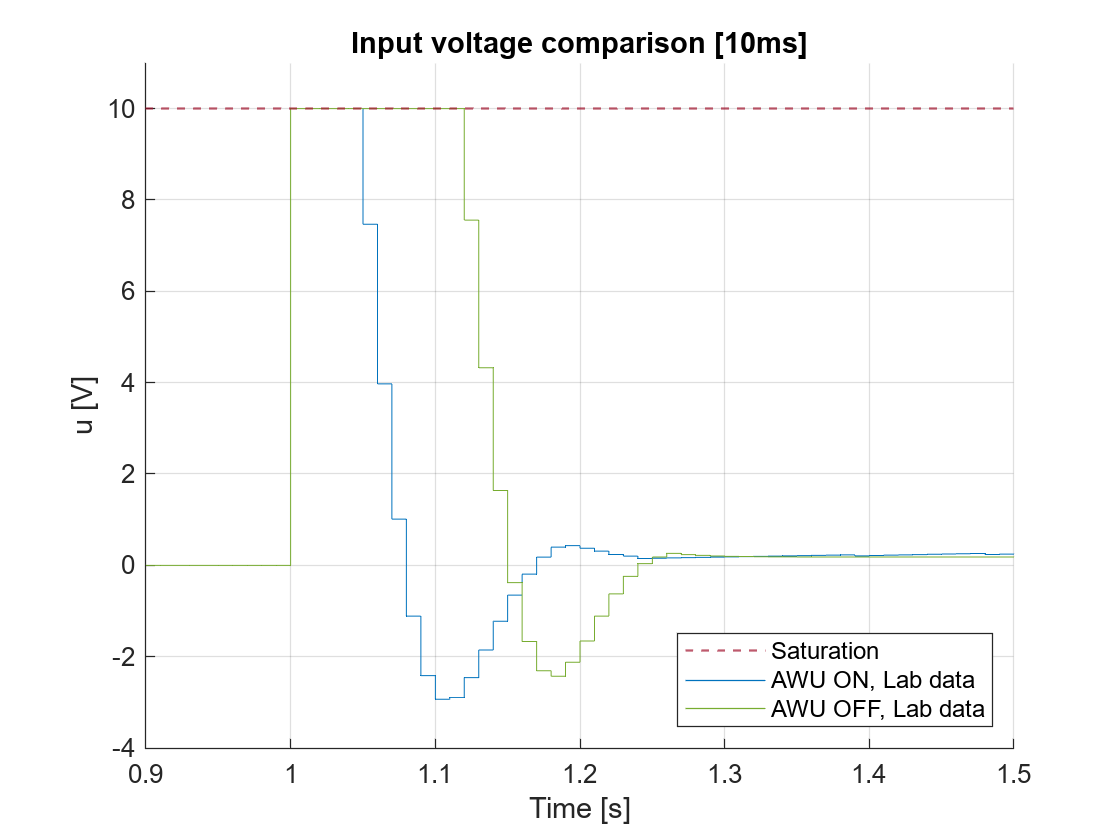


figure
hold on

yline(10, '--','Color',	"#A2142F",'LineWidth',0.8)
stairs(pid_nominal_track.AWU.BE.thl_meas.time, pid_nominal_track.AWU.BE.u.signals.values ,'Color',	'#0072BD')
stairs(pid_nominal_track.NOAWU.BE.thl_meas.time, pid_nominal_track.NOAWU.BE.u.signals.values ,'Color',	"#77AC30");


legend('Saturation', 'AWU ON, Lab data','AWU OFF, Lab data', 'Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('u [V]')
title('Input voltage comparison [10ms]')
axis([0.9 1.5 -4 11])
exportgraphics(gcf,'Figures\04_PID_AWU\input_voltage.pdf','ContentType','vector')

1 Plot: FF BE 10ms Lab data, No FF BE 10ms corbioli Tracking error FF vs no FF 

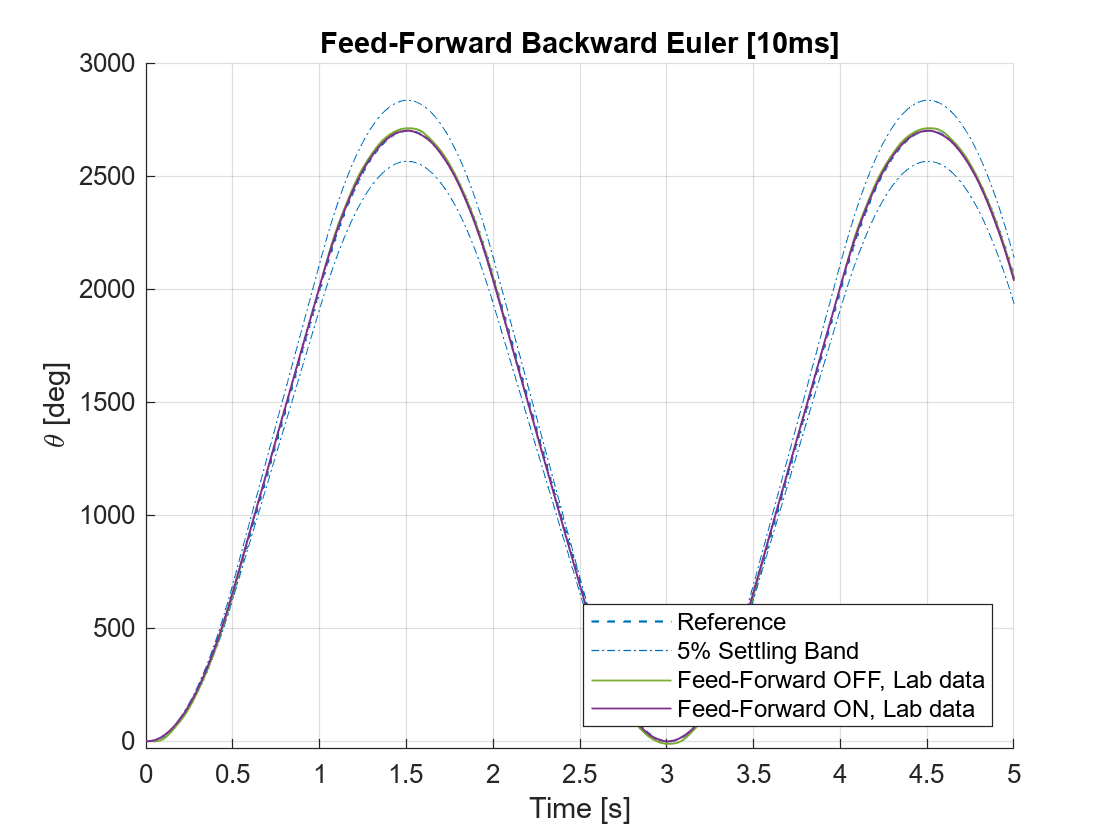

load("LAB_Results\corby\RealSim3113_feedForward.mat")
lab.no_ff=out_no_ff;
lab.ff=out_ff;
load("LAB_Results\corby\SIM2113_PID_feedForward.mat")
manual.no_ff=out_no_ff;
manual.ff=out_ff;


figure
hold on
% Ref
stairs(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.signals.values,'--','LineWidth',0.8)
plot(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.signals.values*1.05,'-.','Color',"#0072BD")
plot(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.signals.values*0.95,'-.','Color',"#0072BD")
%plot(lab.no_ff.thl_ref.time, lab.no_ff.thl_ref.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(lab.no_ff.thl_meas.time, lab.no_ff.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(lab.ff.thl_meas.time, lab.ff.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','Feed-Forward OFF, Lab data','Feed-Forward ON, Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Feed-Forward Backward Euler [10ms]')
axis([0 5 -30 3000])
exportgraphics(gcf,'Figures\05_PID_FFW\ffw_comparison.pdf','ContentType','vector')

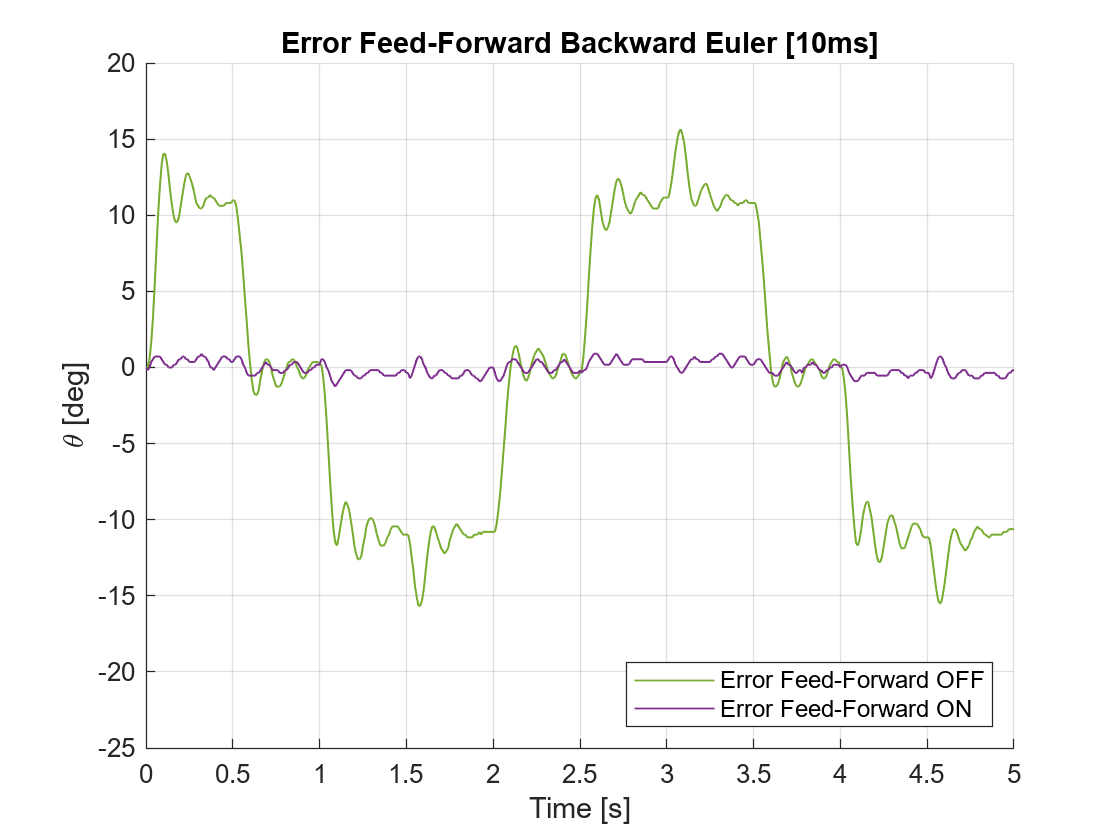


figure
hold on
% Data
plot(lab.no_ff.thl_meas.time, lab.no_ff.thl_ref.signals.values-lab.no_ff.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(lab.ff.thl_meas.time, lab.ff.thl_ref.signals.values-lab.ff.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Error Feed-Forward OFF','Error Feed-Forward ON','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Error Feed-Forward Backward Euler [10ms]')
axis([0 5 -25 20])
exportgraphics(gcf,'Figures\05_PID_FFW\ffw_error.pdf','ContentType','vector')

#### CT SS design - 40,70,120 nominal 

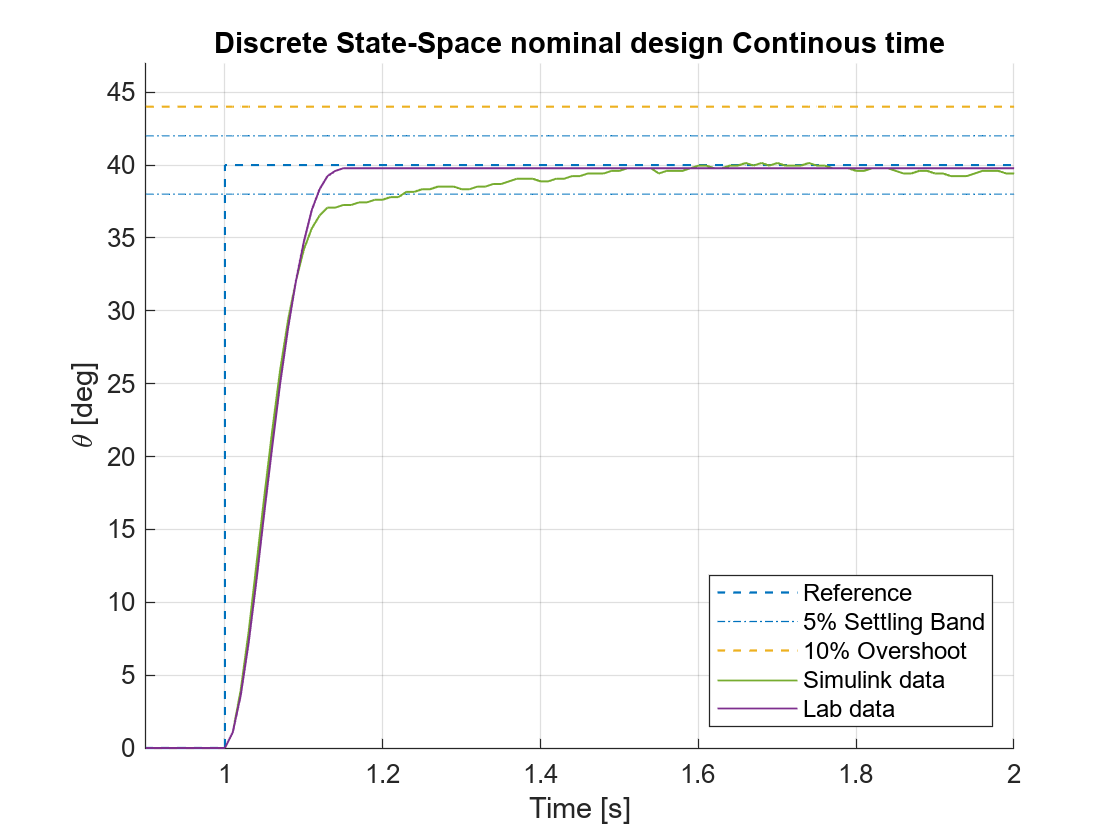

load("LAB_Results\R04_nominal_estimator_CT.mat")

figure
hold on
% Ref
stairs(SS_nominal_track.CT.deg_40.thref.time, SS_nominal_track.CT.deg_40.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.CT.deg_40.thref.time-1, SS_nominal_track.CT.deg_40.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.CT.deg_40.thref.time-1, SS_nominal_track.CT.deg_40.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.CT.deg_40.thref.time-1, SS_nominal_track.CT.deg_40.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.CT.deg_40.thl_meas.time, ss_nominal_track_manual.CT.deg_40.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.CT.deg_40.thl_meas.time, SS_nominal_track.CT.deg_40.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal design Continous time')
axis([0.9 2 0 47])
exportgraphics(gcf,'Figures\06_SS_Nominal_CT\CT_40.pdf','ContentType','vector')

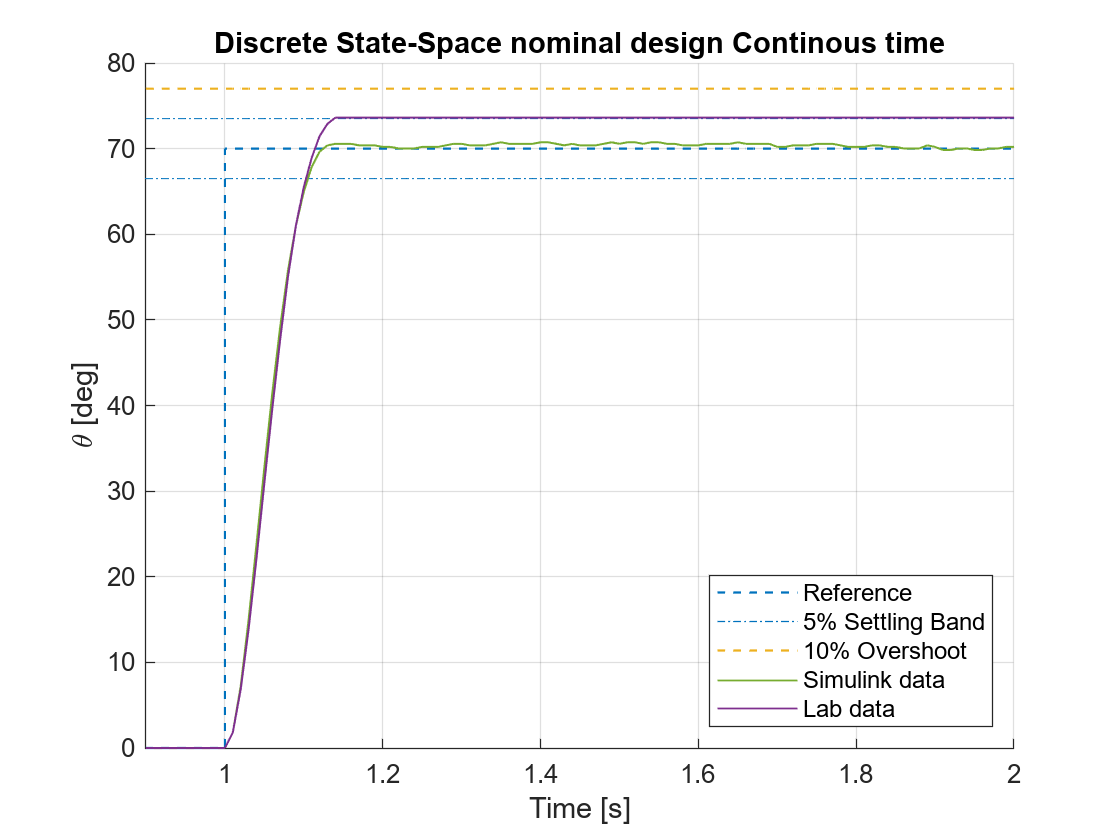


figure
hold on
% Ref
stairs(SS_nominal_track.CT.deg_70.thref.time, SS_nominal_track.CT.deg_70.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.CT.deg_70.thref.time-1, SS_nominal_track.CT.deg_70.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.CT.deg_70.thref.time-1, SS_nominal_track.CT.deg_70.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.CT.deg_70.thref.time-1, SS_nominal_track.CT.deg_70.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.CT.deg_70.thl_meas.time, ss_nominal_track_manual.CT.deg_70.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.CT.deg_70.thl_meas.time, SS_nominal_track.CT.deg_70.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal design Continous time')
axis([0.9 2 0 80])
exportgraphics(gcf,'Figures\06_SS_Nominal_CT\CT_70.pdf','ContentType','vector')

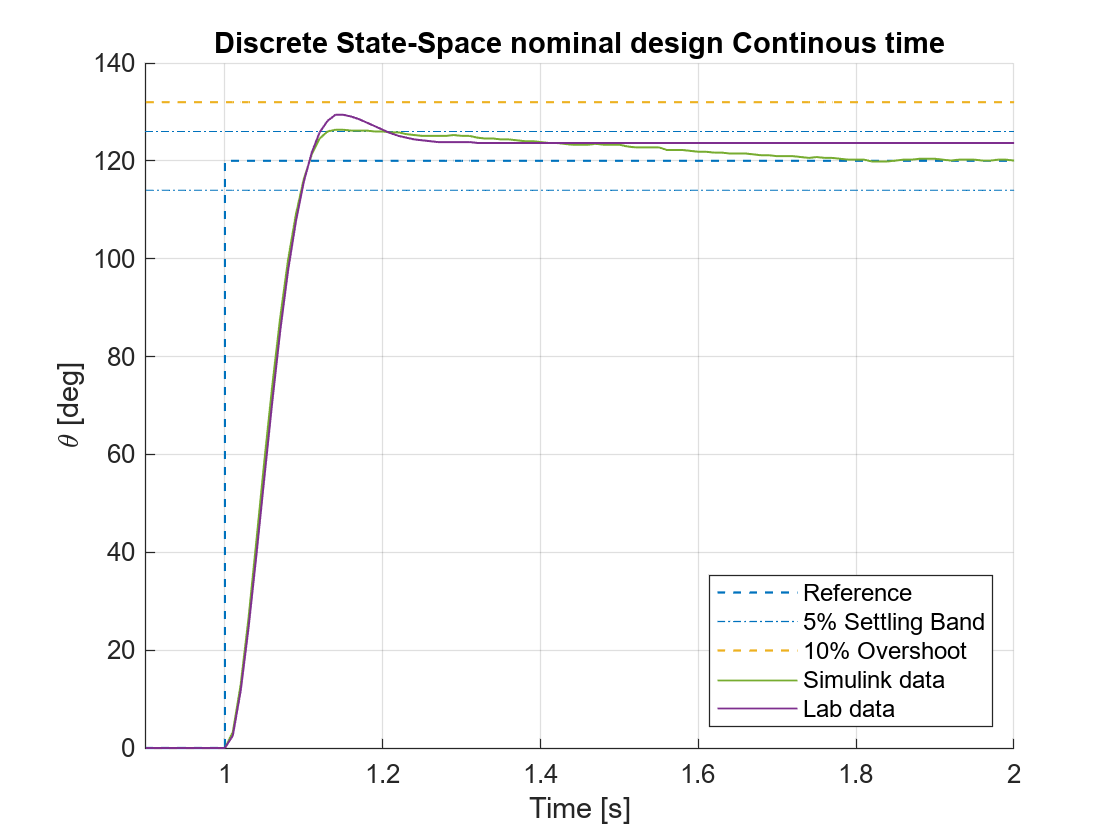


figure
hold on
% Ref
stairs(SS_nominal_track.CT.deg_120.thref.time, SS_nominal_track.CT.deg_120.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.CT.deg_120.thref.time-1, SS_nominal_track.CT.deg_120.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.CT.deg_120.thref.time-1, SS_nominal_track.CT.deg_120.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.CT.deg_120.thref.time-1, SS_nominal_track.CT.deg_120.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.CT.deg_120.thl_meas.time, ss_nominal_track_manual.CT.deg_120.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.CT.deg_120.thl_meas.time, SS_nominal_track.CT.deg_120.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal design Continous time')
axis([0.9 2 0 140])
exportgraphics(gcf,'Figures\06_SS_Nominal_CT\CT_120.pdf','ContentType','vector')

#### CT SS design - 40,70,120 robust

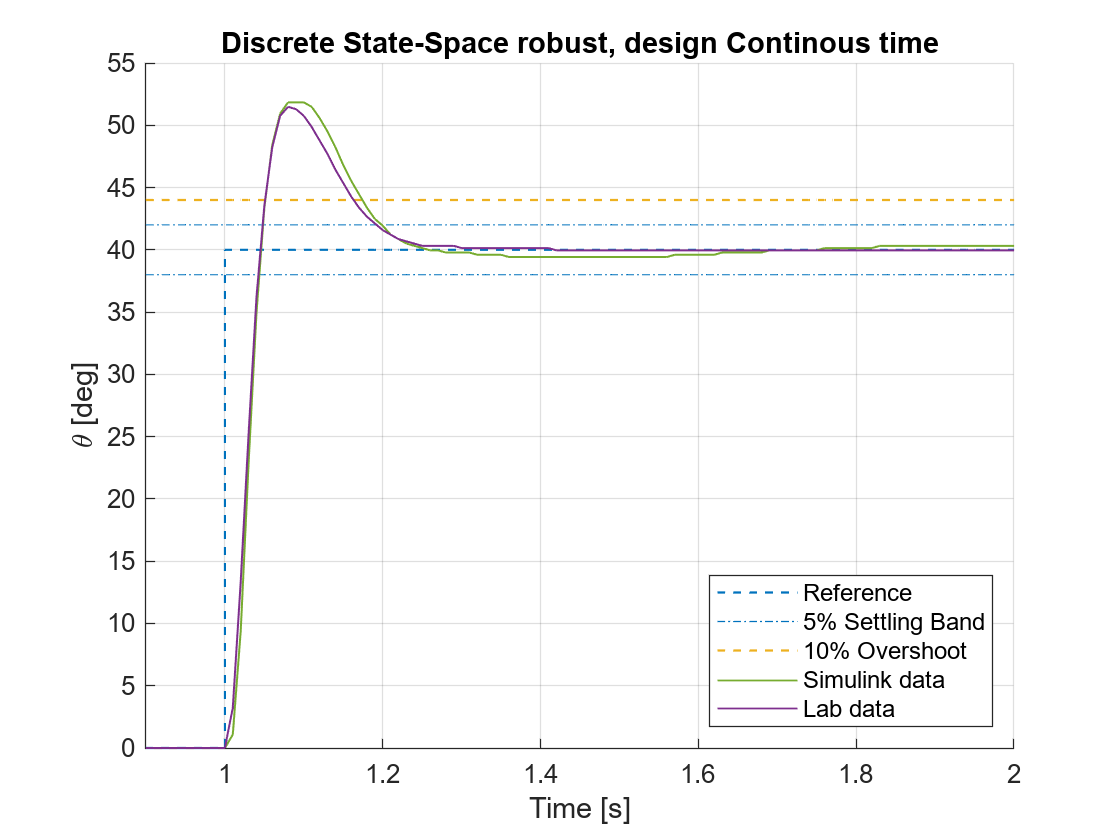

load("LAB_Results\R06_robust_track_CT.mat")

figure
hold on
% Ref
stairs(robust_track.CT.deg_40.thref.time, robust_track.CT.deg_40.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.CT.deg_40.thref.time-1, robust_track.CT.deg_40.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.CT.deg_40.thref.time-1, robust_track.CT.deg_40.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.CT.deg_40.thref.time-1, robust_track.CT.deg_40.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.CT.deg_40.thl_meas.time, ss_robust_track_manual.CT.deg_40.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.CT.deg_40.thl_meas.time, robust_track.CT.deg_40.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, design Continous time')
axis([0.9 2 0 55])
exportgraphics(gcf,'Figures\07_SS_robust_CT\CT_40.pdf','ContentType','vector')

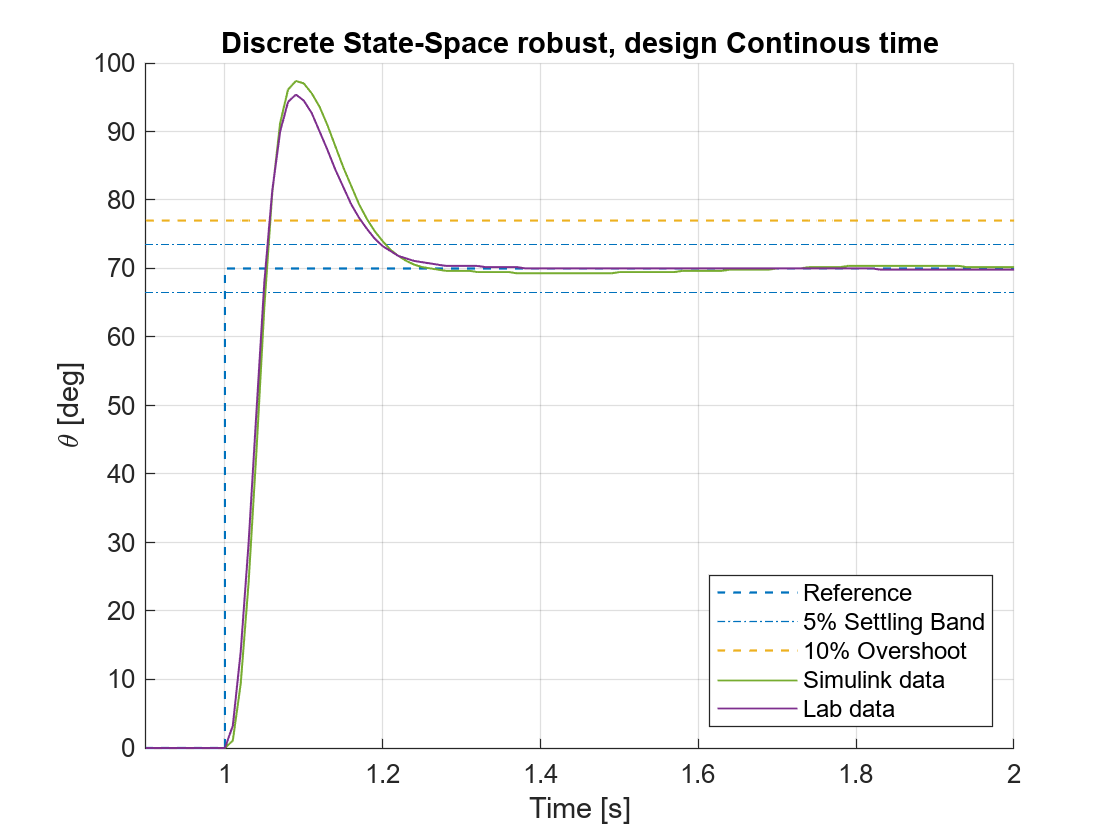


figure
hold on
% Ref
stairs(robust_track.CT.deg_70.thref.time, robust_track.CT.deg_70.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.CT.deg_70.thref.time-1, robust_track.CT.deg_70.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.CT.deg_70.thref.time-1, robust_track.CT.deg_70.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.CT.deg_70.thref.time-1, robust_track.CT.deg_70.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.CT.deg_70.thl_meas.time, ss_robust_track_manual.CT.deg_70.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.CT.deg_70.thl_meas.time, robust_track.CT.deg_70.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, design Continous time')
axis([0.9 2 0 100])
exportgraphics(gcf,'Figures\07_SS_robust_CT\CT_70.pdf','ContentType','vector')

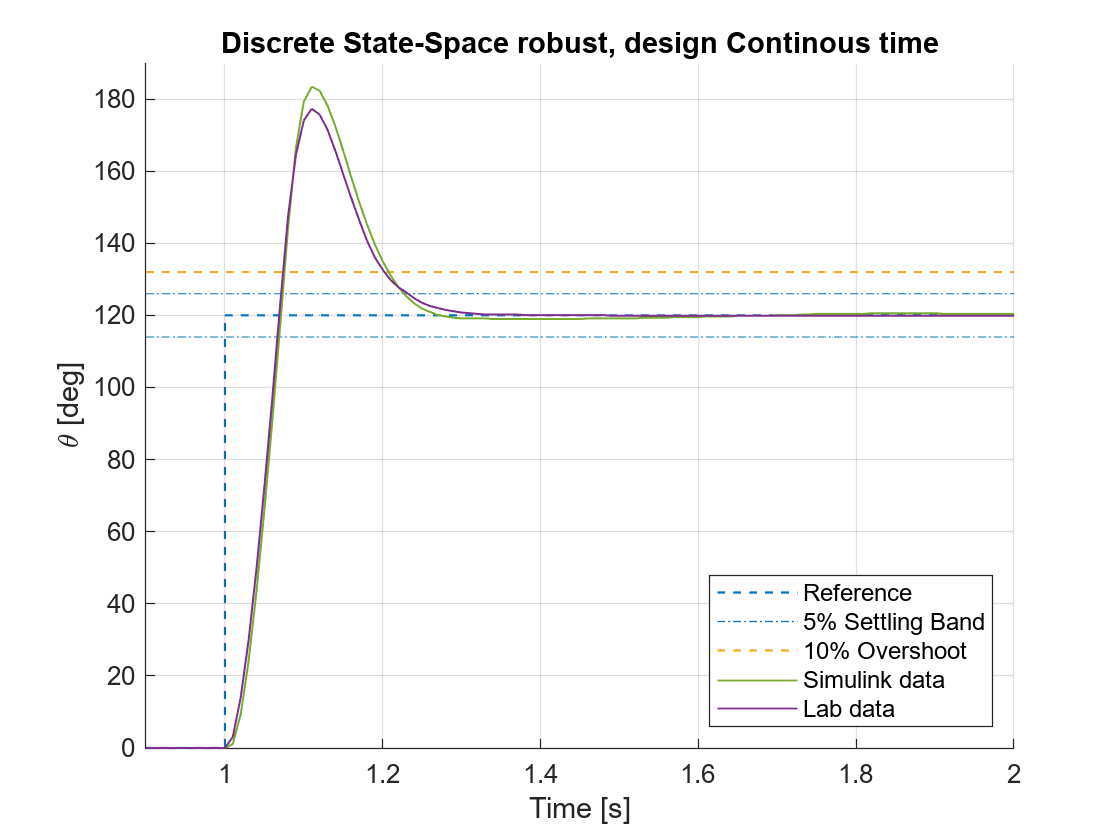


figure
hold on
% Ref
stairs(robust_track.CT.deg_120.thref.time, robust_track.CT.deg_120.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.CT.deg_120.thref.time-1, robust_track.CT.deg_120.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.CT.deg_120.thref.time-1, robust_track.CT.deg_120.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.CT.deg_120.thref.time-1, robust_track.CT.deg_120.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.CT.deg_120.thl_meas.time, ss_robust_track_manual.CT.deg_120.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.CT.deg_120.thl_meas.time, robust_track.CT.deg_120.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, design Continous time')
axis([0.9 2 0 190])
exportgraphics(gcf,'Figures\07_SS_robust_CT\CT_120.pdf','ContentType','vector')

DT emulation SS nominal - All Ts and disc

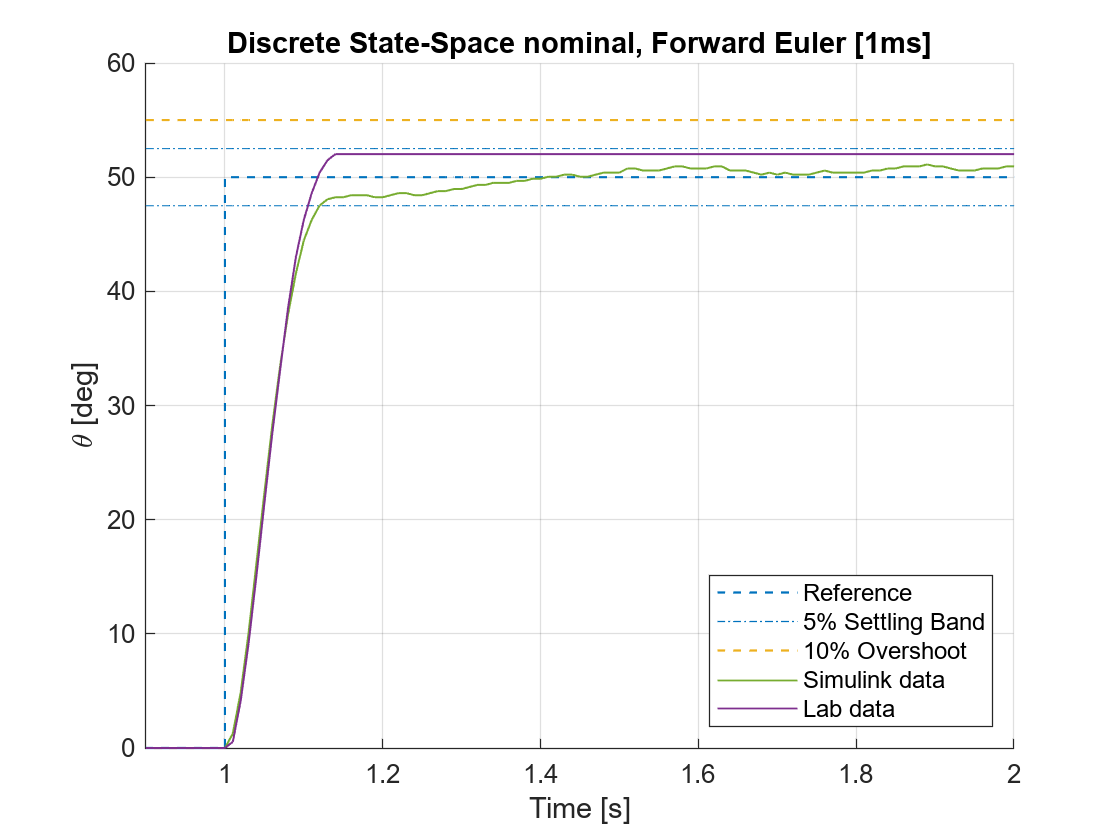

load("LAB_Results\R05_nominal_estimator_DT.mat")

figure
hold on
% Ref
stairs(SS_nominal_track.FE.T1.thref.time, SS_nominal_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.FE.T1.thref.time-1, SS_nominal_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.FE.T1.thref.time-1, SS_nominal_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.FE.T1.thref.time-1, SS_nominal_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.FE.T1.thl_meas.time, ss_nominal_track_manual.FE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.FE.T1.thl_meas.time, SS_nominal_track.FE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Forward Euler [1ms]')
axis([0.9 2 0 60])
exportgraphics(gcf,'Figures\08_SS_nominal_emulation\FE_01.pdf','ContentType','vector')

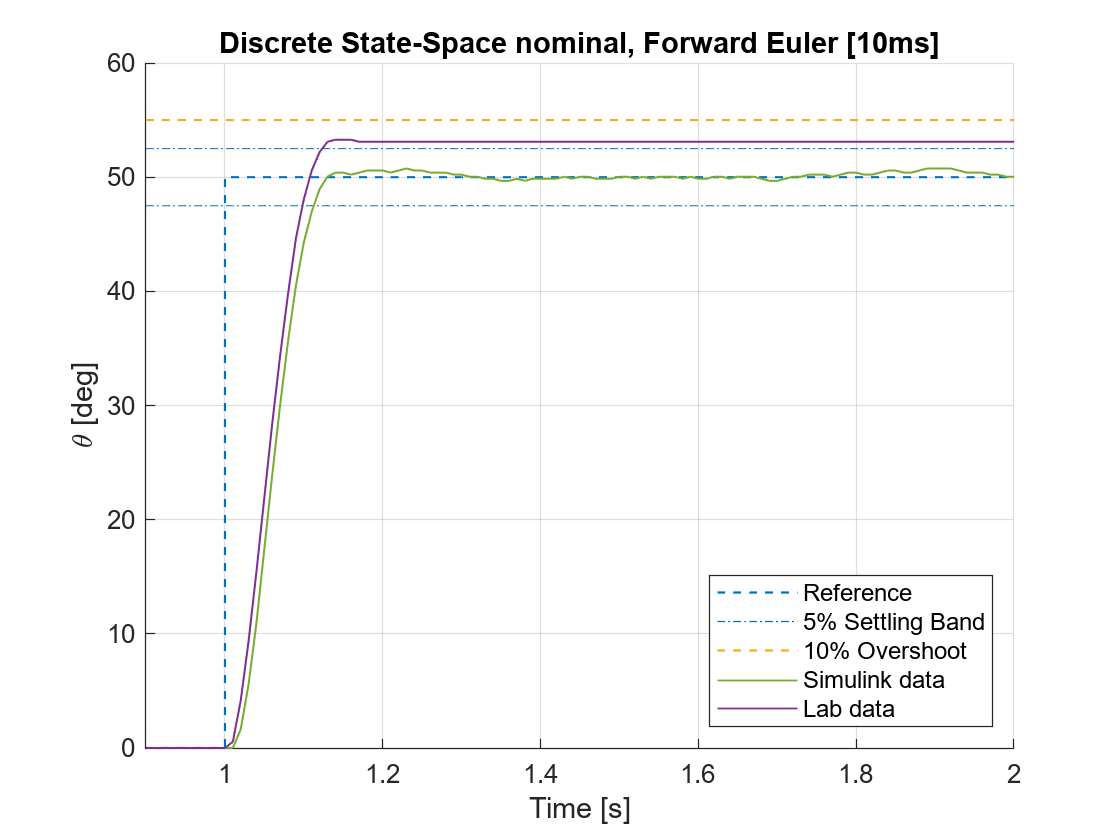

figure
hold on
% Ref
stairs(SS_nominal_track.FE.T2.thref.time, SS_nominal_track.FE.T2.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.FE.T2.thref.time-1, SS_nominal_track.FE.T2.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.FE.T2.thref.time-1, SS_nominal_track.FE.T2.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.FE.T2.thref.time-1, SS_nominal_track.FE.T2.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.FE.T2.thl_meas.time, ss_nominal_track_manual.FE.T2.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.FE.T2.thl_meas.time, SS_nominal_track.FE.T2.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Forward Euler [10ms]')
axis([0.9 2 0 60])
exportgraphics(gcf,'Figures\08_SS_nominal_emulation\FE_10.pdf','ContentType','vector')

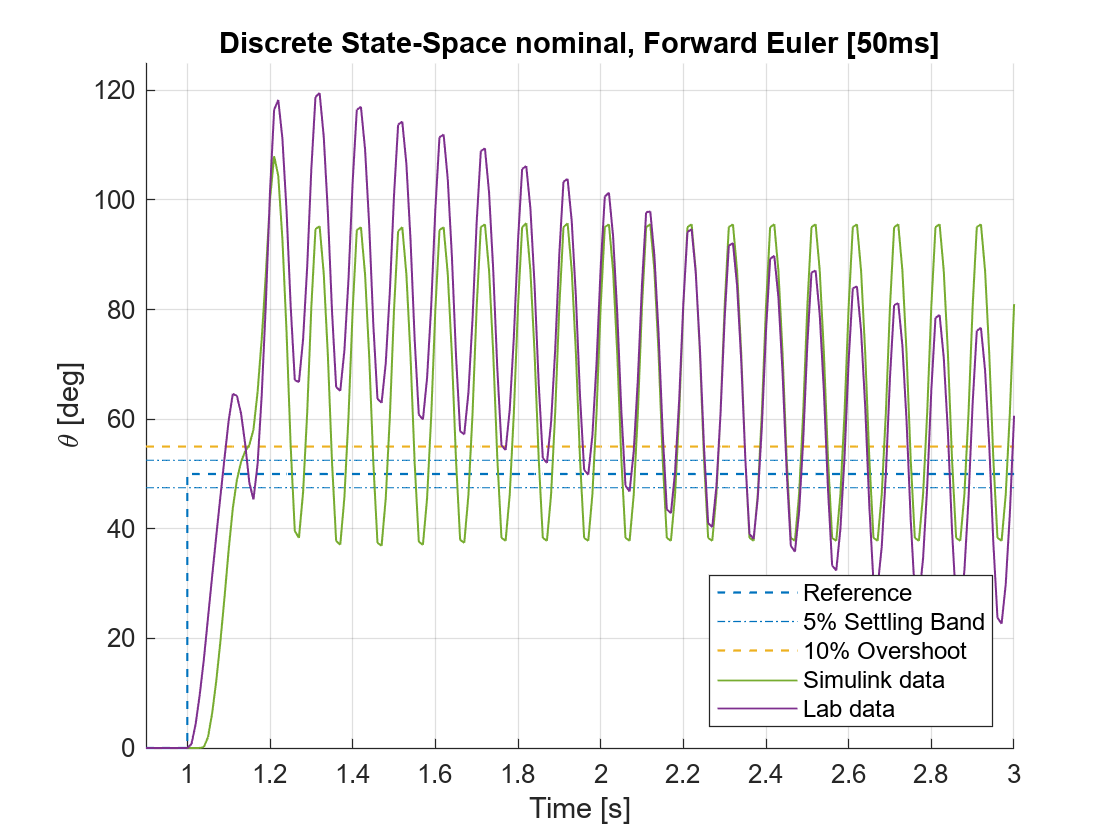

figure
hold on
% Ref
stairs(SS_nominal_track.FE.T3.thref.time, SS_nominal_track.FE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.FE.T3.thref.time-1, SS_nominal_track.FE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.FE.T3.thref.time-1, SS_nominal_track.FE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.FE.T3.thref.time-1, SS_nominal_track.FE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.FE.T3.thl_meas.time, ss_nominal_track_manual.FE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.FE.T3.thl_meas.time, SS_nominal_track.FE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Forward Euler [50ms]')
axis([0.9 3 0 125])
exportgraphics(gcf,'Figures\08_SS_nominal_emulation\FE_50.pdf','ContentType','vector')

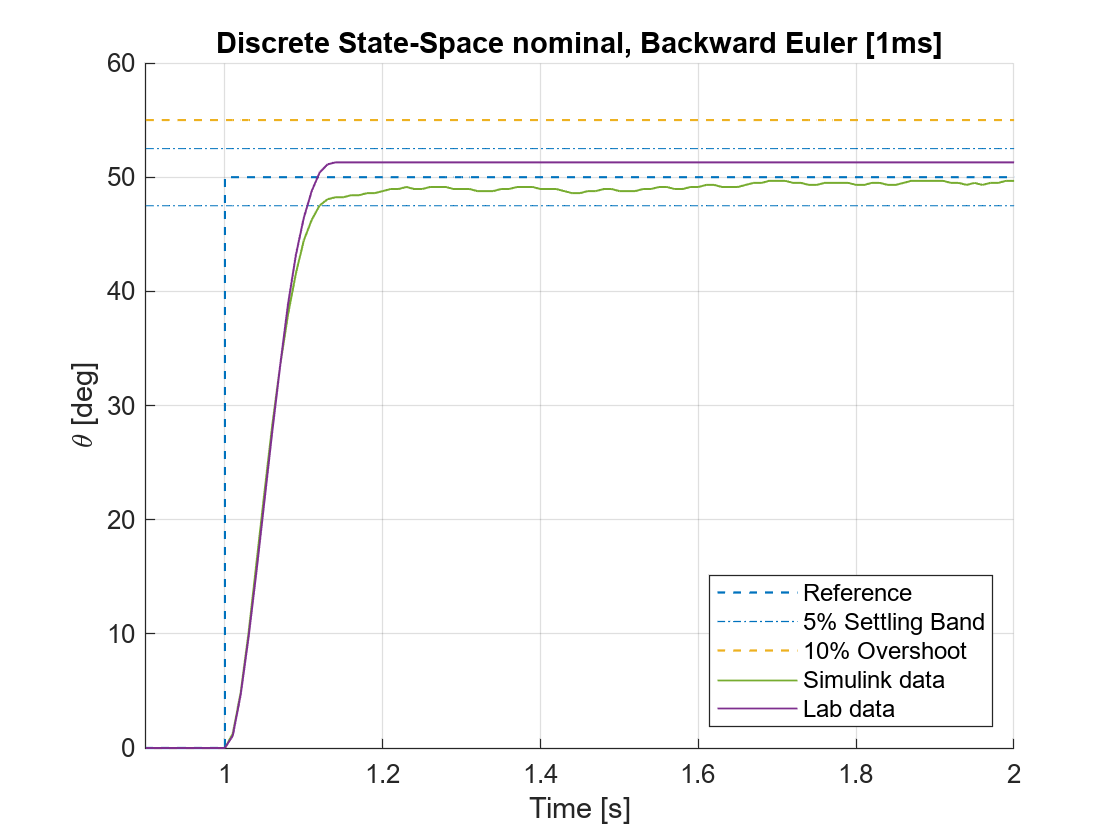



figure
hold on
% Ref
stairs(SS_nominal_track.BE.T1.thref.time, SS_nominal_track.BE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.BE.T1.thref.time-1, SS_nominal_track.BE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.BE.T1.thref.time-1, SS_nominal_track.BE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.BE.T1.thref.time-1, SS_nominal_track.BE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.BE.T1.thl_meas.time, ss_nominal_track_manual.BE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.BE.T1.thl_meas.time, SS_nominal_track.BE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Backward Euler [1ms]')
axis([0.9 2 0 60])
exportgraphics(gcf,'Figures\08_SS_nominal_emulation\BE_01.pdf','ContentType','vector')

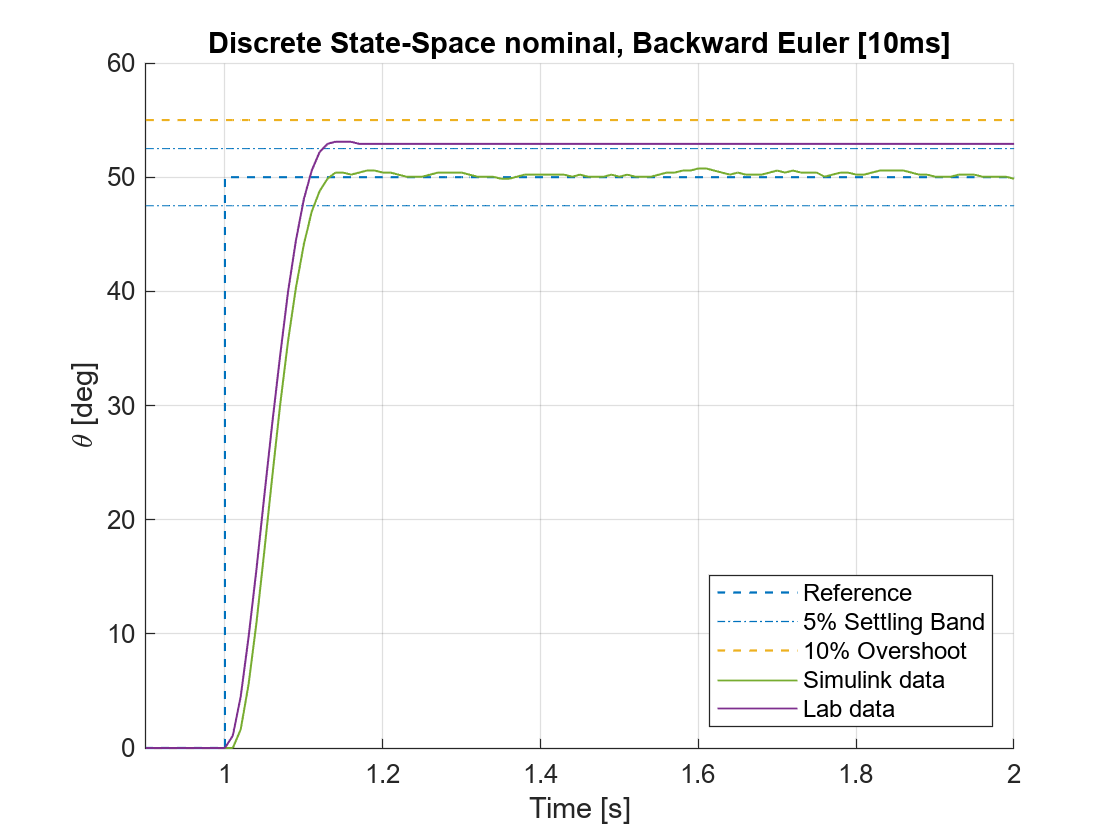

figure
hold on
% Ref
stairs(SS_nominal_track.BE.T2.thref.time, SS_nominal_track.BE.T2.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.BE.T2.thref.time-1, SS_nominal_track.BE.T2.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.BE.T2.thref.time-1, SS_nominal_track.BE.T2.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.BE.T2.thref.time-1, SS_nominal_track.BE.T2.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.BE.T2.thl_meas.time, ss_nominal_track_manual.BE.T2.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.BE.T2.thl_meas.time, SS_nominal_track.BE.T2.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Backward Euler [10ms]')
axis([0.9 2 0 60])
exportgraphics(gcf,'Figures\08_SS_nominal_emulation\BE_10.pdf','ContentType','vector')

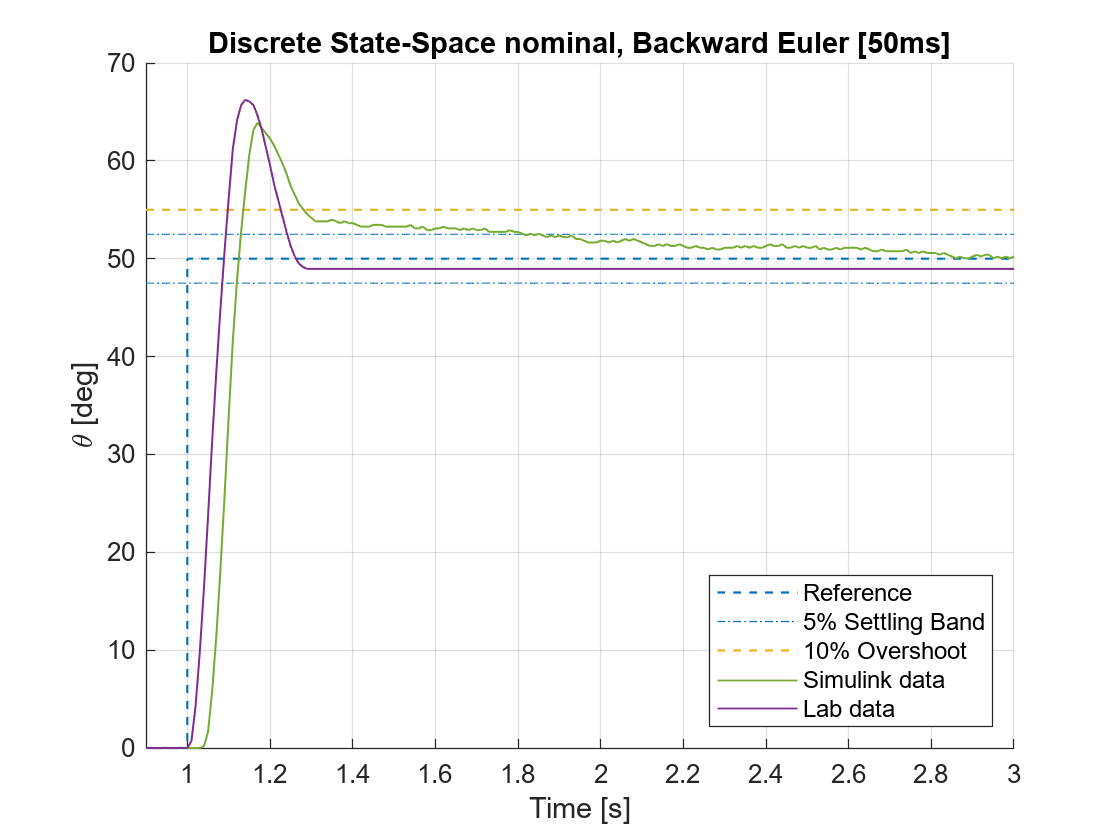

figure
hold on
% Ref
stairs(SS_nominal_track.BE.T3.thref.time, SS_nominal_track.BE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(SS_nominal_track.BE.T3.thref.time-1, SS_nominal_track.BE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(SS_nominal_track.BE.T3.thref.time-1, SS_nominal_track.BE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(SS_nominal_track.BE.T3.thref.time-1, SS_nominal_track.BE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_nominal_track_manual.BE.T3.thl_meas.time, ss_nominal_track_manual.BE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(SS_nominal_track.BE.T3.thl_meas.time, SS_nominal_track.BE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Backward Euler [50ms]')
axis([0.9 3 0 70])
exportgraphics(gcf,'Figures\08_SS_nominal_emulation\BE_50.pdf','ContentType','vector')

#### DT emulation SS robust - All Ts and disc

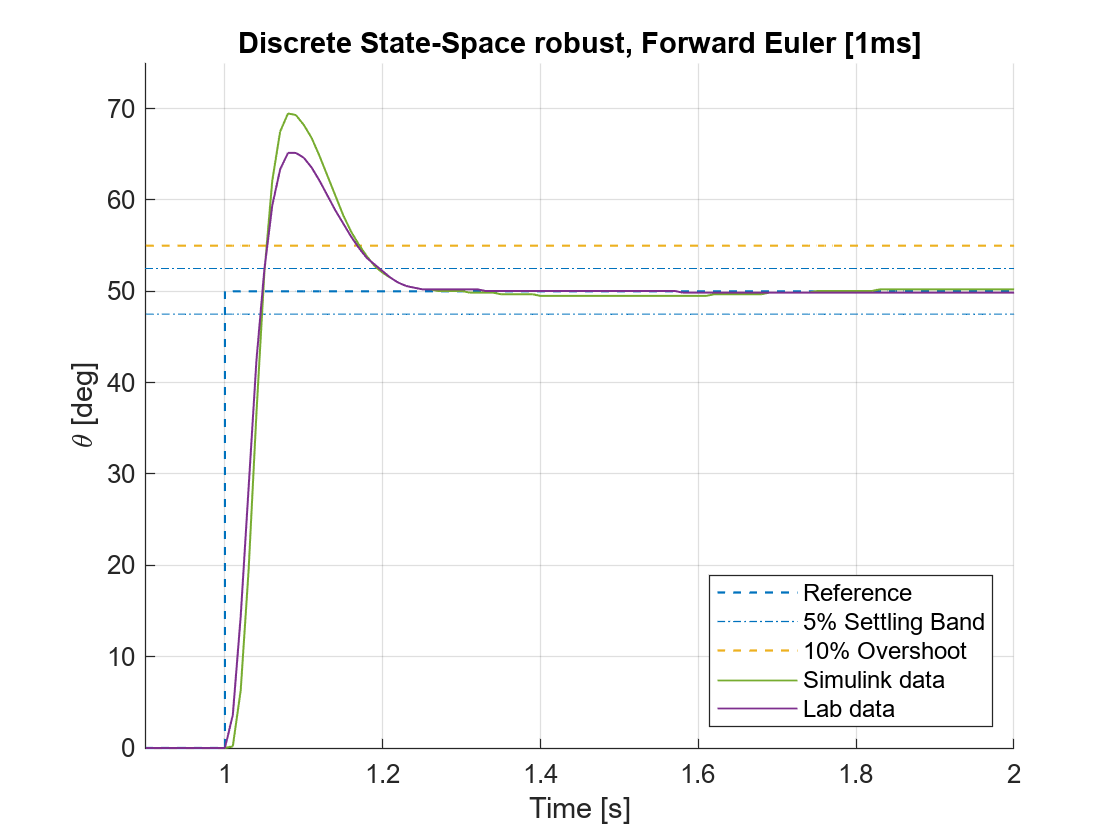

load("LAB_Results\R07_robust_track_FE.mat")

figure
hold on
% Ref
stairs(robust_track.FE.T1.thref.time, robust_track.FE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.FE.T1.thref.time-1, robust_track.FE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.FE.T1.thref.time-1, robust_track.FE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.FE.T1.thref.time-1, robust_track.FE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.FE.T1.thl_meas.time, ss_robust_track_manual.FE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.FE.T1.thl_meas.time, robust_track.FE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Forward Euler [1ms]')
axis([0.9 2 0 75])
exportgraphics(gcf,'Figures\09_SS_robust_emulation\FE_01.pdf','ContentType','vector')

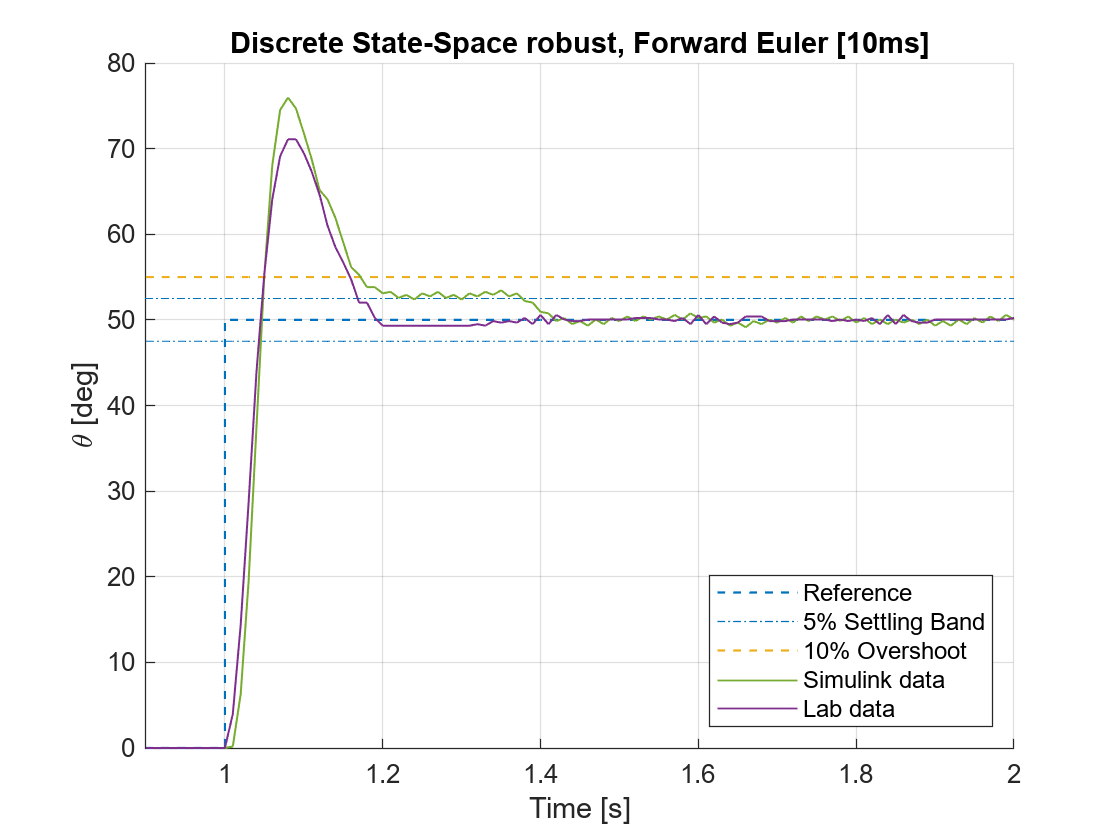

figure
hold on
% Ref
stairs(robust_track.FE.T2.thref.time, robust_track.FE.T2.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.FE.T2.thref.time-1, robust_track.FE.T2.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.FE.T2.thref.time-1, robust_track.FE.T2.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.FE.T2.thref.time-1, robust_track.FE.T2.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.FE.T2.thl_meas.time, ss_robust_track_manual.FE.T2.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.FE.T2.thl_meas.time, robust_track.FE.T2.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Forward Euler [10ms]')
axis([0.9 2 0 80])
exportgraphics(gcf,'Figures\09_SS_robust_emulation\FE_10.pdf','ContentType','vector')

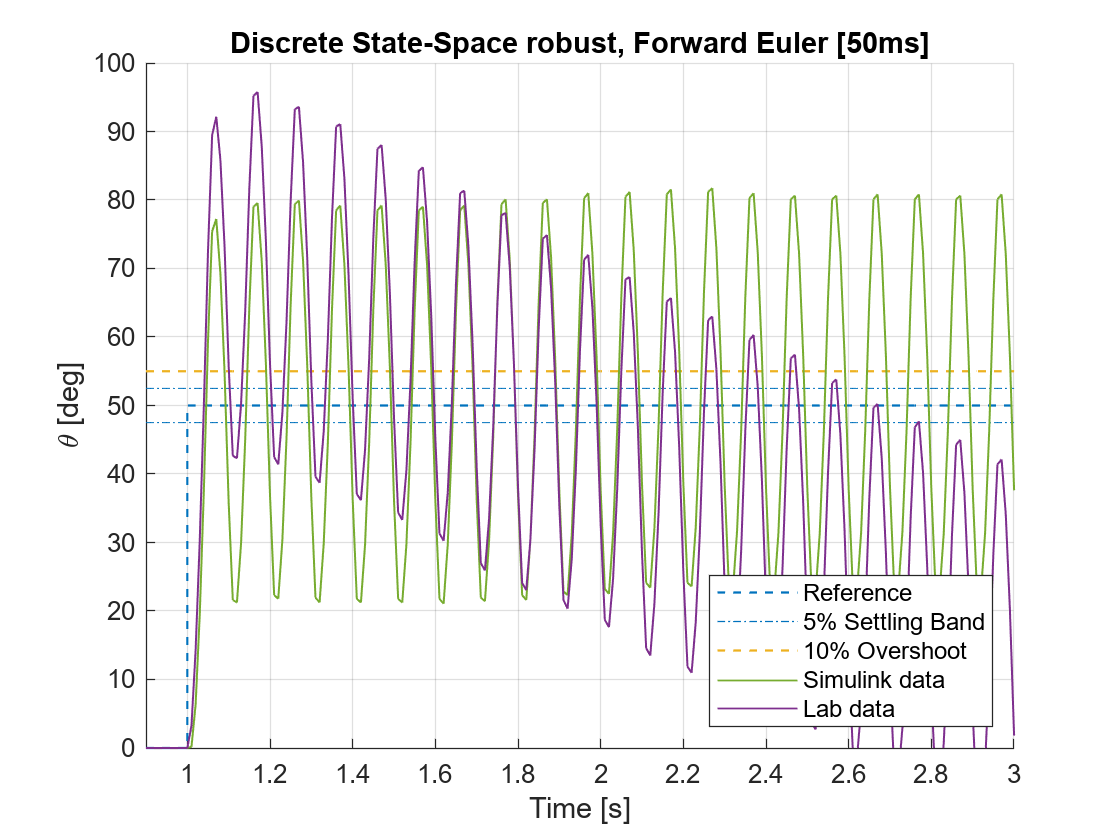

figure
hold on
% Ref
stairs(robust_track.FE.T3.thref.time, robust_track.FE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.FE.T3.thref.time-1, robust_track.FE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.FE.T3.thref.time-1, robust_track.FE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.FE.T3.thref.time-1, robust_track.FE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.FE.T3.thl_meas.time, ss_robust_track_manual.FE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.FE.T3.thl_meas.time, robust_track.FE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Forward Euler [50ms]')
axis([0.9 3 0 100])
exportgraphics(gcf,'Figures\09_SS_robust_emulation\FE_50.pdf','ContentType','vector')

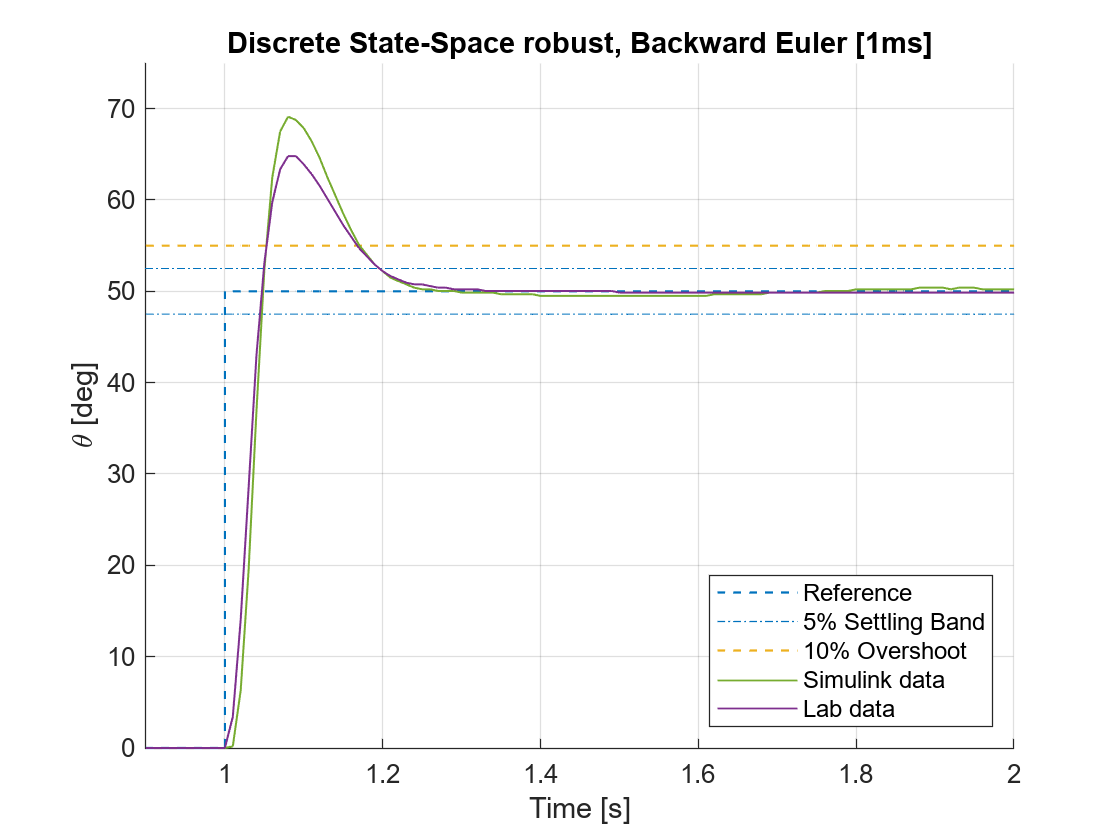




load("LAB_Results\R08_robust_track_BE.mat")



figure
hold on
% Ref
stairs(robust_track.BE.T1.thref.time, robust_track.BE.T1.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.BE.T1.thref.time-1, robust_track.BE.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.BE.T1.thref.time-1, robust_track.BE.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.BE.T1.thref.time-1, robust_track.BE.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.BE.T1.thl_meas.time, ss_robust_track_manual.BE.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.BE.T1.thl_meas.time, robust_track.BE.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Backward Euler [1ms]')
axis([0.9 2 0 75])
exportgraphics(gcf,'Figures\09_SS_robust_emulation\BE_01.pdf','ContentType','vector')

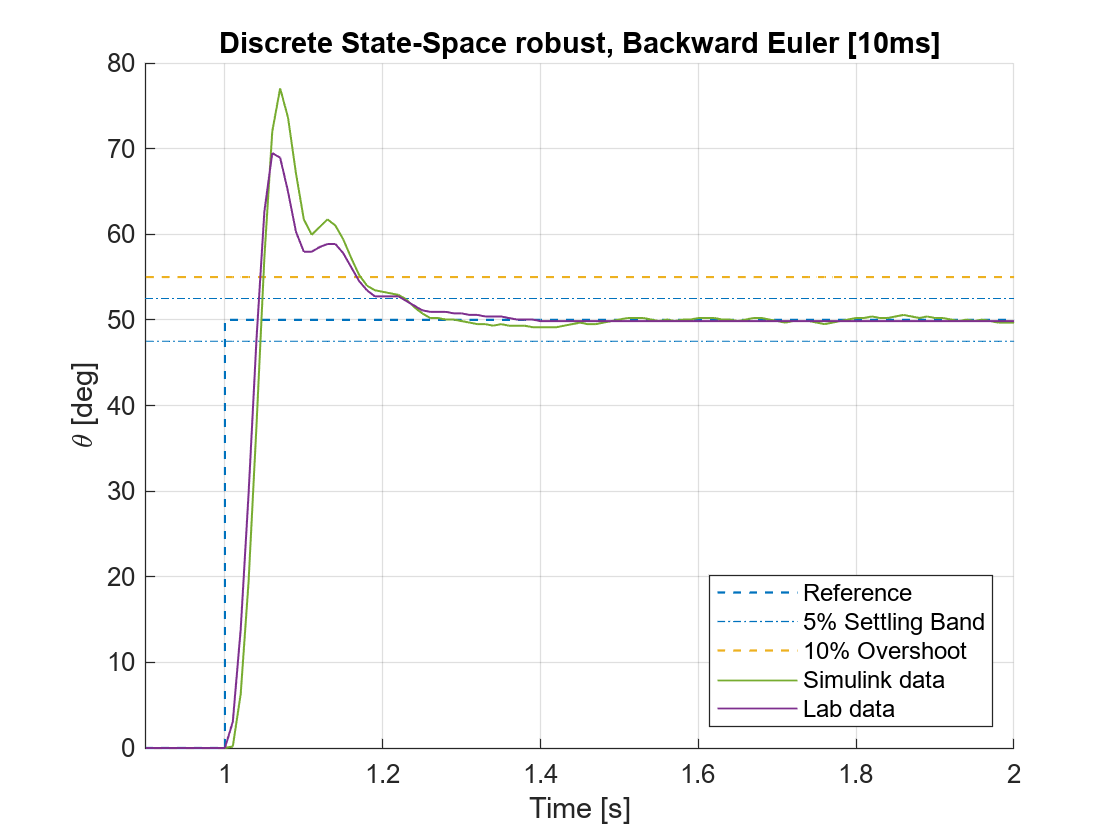

figure
hold on
% Ref
stairs(robust_track.BE.T2.thref.time, robust_track.BE.T2.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.BE.T2.thref.time-1, robust_track.BE.T2.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.BE.T2.thref.time-1, robust_track.BE.T2.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.BE.T2.thref.time-1, robust_track.BE.T2.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.BE.T2.thl_meas.time, ss_robust_track_manual.BE.T2.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.BE.T2.thl_meas.time, robust_track.BE.T2.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Backward Euler [10ms]')
axis([0.9 2 0 80])
exportgraphics(gcf,'Figures\09_SS_robust_emulation\BE_10.pdf','ContentType','vector')

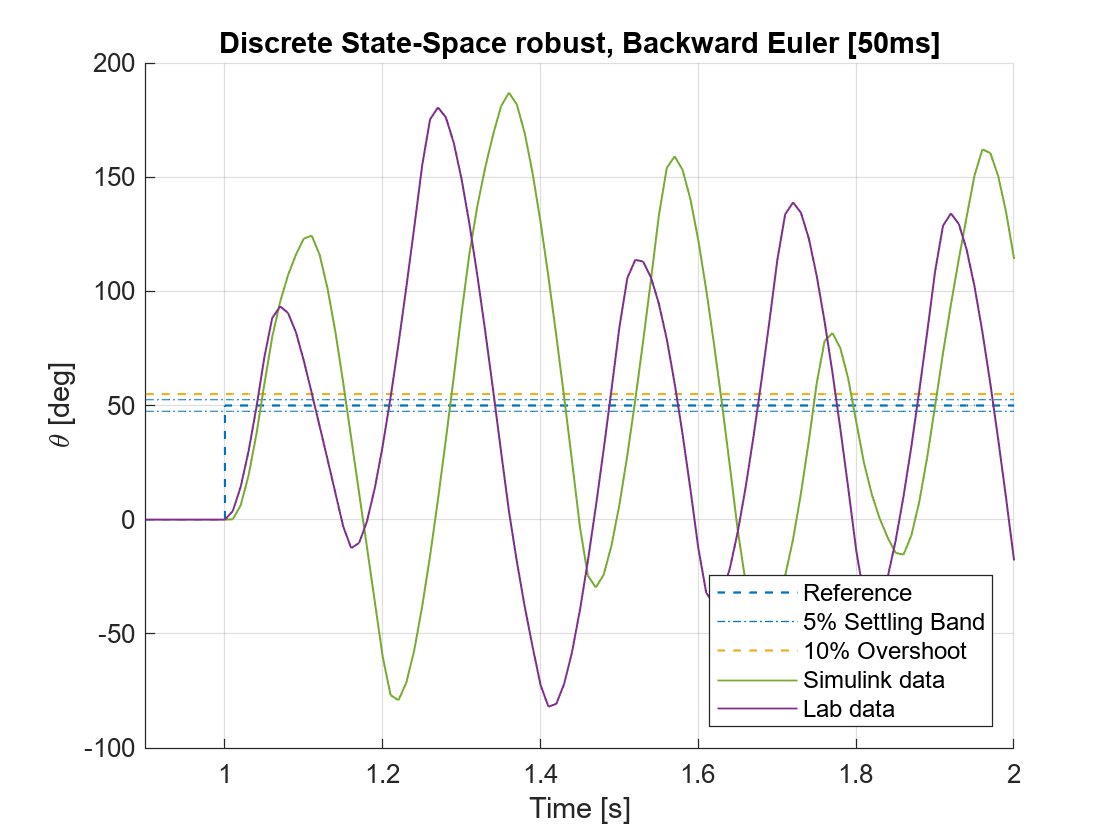

figure
hold on
% Ref
stairs(robust_track.BE.T3.thref.time, robust_track.BE.T3.thref.signals.values,'--','LineWidth',0.8)
plot(robust_track.BE.T3.thref.time-1, robust_track.BE.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(robust_track.BE.T3.thref.time-1, robust_track.BE.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(robust_track.BE.T3.thref.time-1, robust_track.BE.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_robust_track_manual.BE.T3.thl_meas.time, ss_robust_track_manual.BE.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(robust_track.BE.T3.thl_meas.time, robust_track.BE.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Backward Euler [50ms]')
axis([0.9 2 -100 200])
exportgraphics(gcf,'Figures\09_SS_robust_emulation\BE_50.pdf','ContentType','vector')

#### 1ms, 10ms, 50ms direct design with nominal (both lab data and simulink)

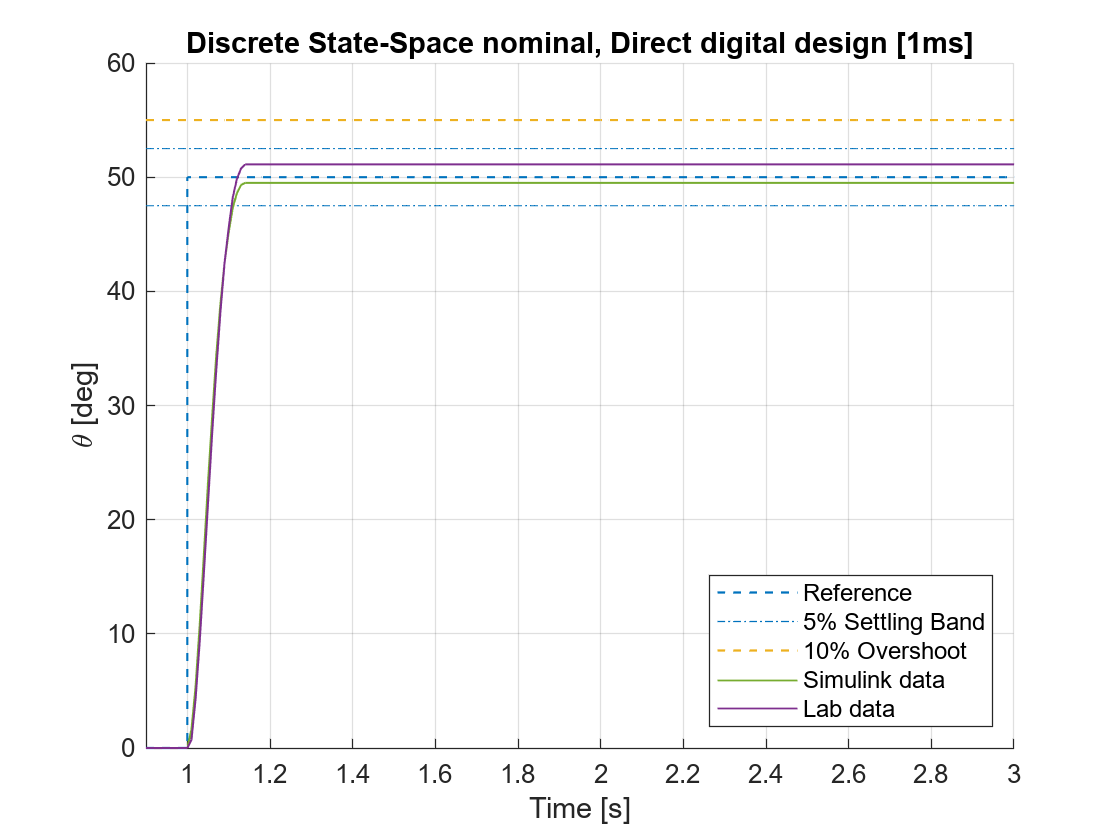

load("LAB_Results\R09_ss_direct_nominal.mat")

figure
hold on
% Ref
stairs(ss_direct_nominal.T1.thref.time, ss_direct_nominal.T1.thref.signals.values,'--','LineWidth',0.8)
plot(ss_direct_nominal.T1.thref.time-1, ss_direct_nominal.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(ss_direct_nominal.T1.thref.time-1, ss_direct_nominal.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(ss_direct_nominal.T1.thref.time-1, ss_direct_nominal.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_direct_nominal_manual.T1.thl_meas.time, ss_direct_nominal_manual.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(ss_direct_nominal.T1.thl_meas.time, ss_direct_nominal.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Direct digital design [1ms]')
axis([0.9 3 0 60])
exportgraphics(gcf,'Figures\10_SS_direct_nominal\01.pdf','ContentType','vector')

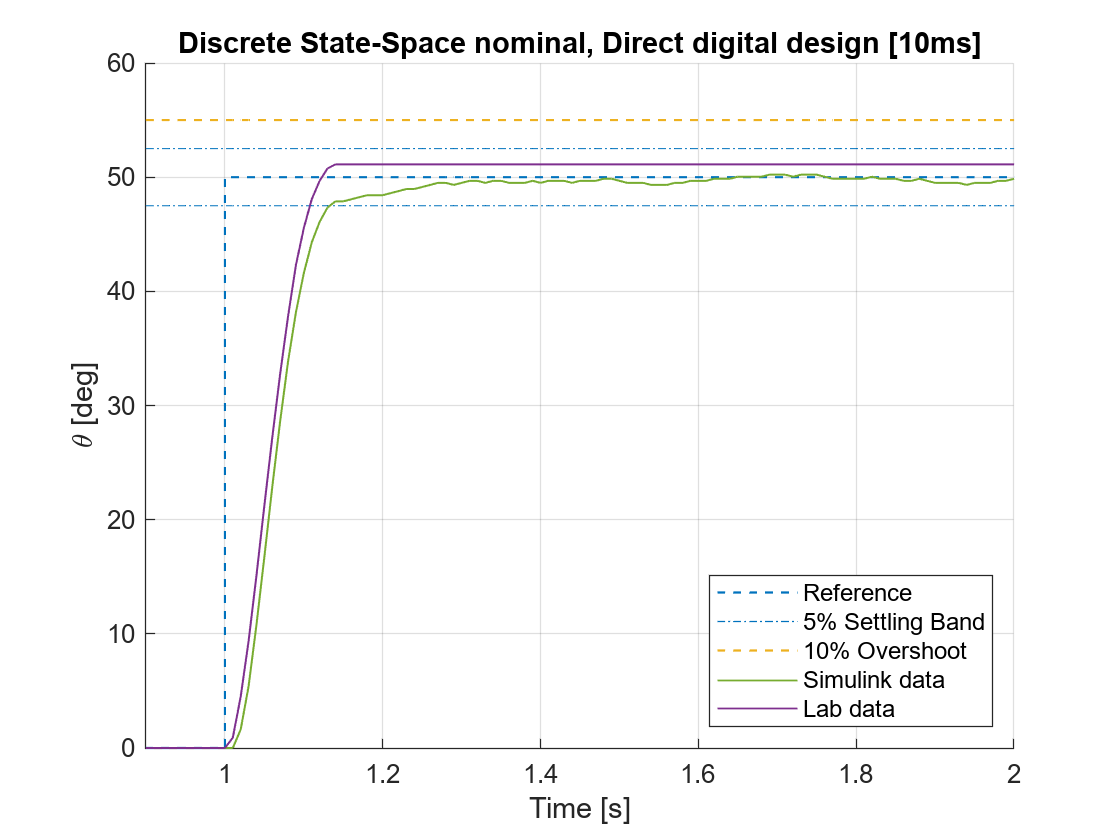

figure
hold on
% Ref
stairs(ss_direct_nominal.T2.thref.time, ss_direct_nominal.T2.thref.signals.values,'--','LineWidth',0.8)
plot(ss_direct_nominal.T2.thref.time-1, ss_direct_nominal.T2.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(ss_direct_nominal.T2.thref.time-1, ss_direct_nominal.T2.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(ss_direct_nominal.T2.thref.time-1, ss_direct_nominal.T2.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_direct_nominal_manual.T2.thl_meas.time, ss_direct_nominal_manual.T2.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(ss_direct_nominal.T2.thl_meas.time, ss_direct_nominal.T2.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Direct digital design [10ms]')
axis([0.9 2 0 60])
exportgraphics(gcf,'Figures\10_SS_direct_nominal\10.pdf','ContentType','vector')

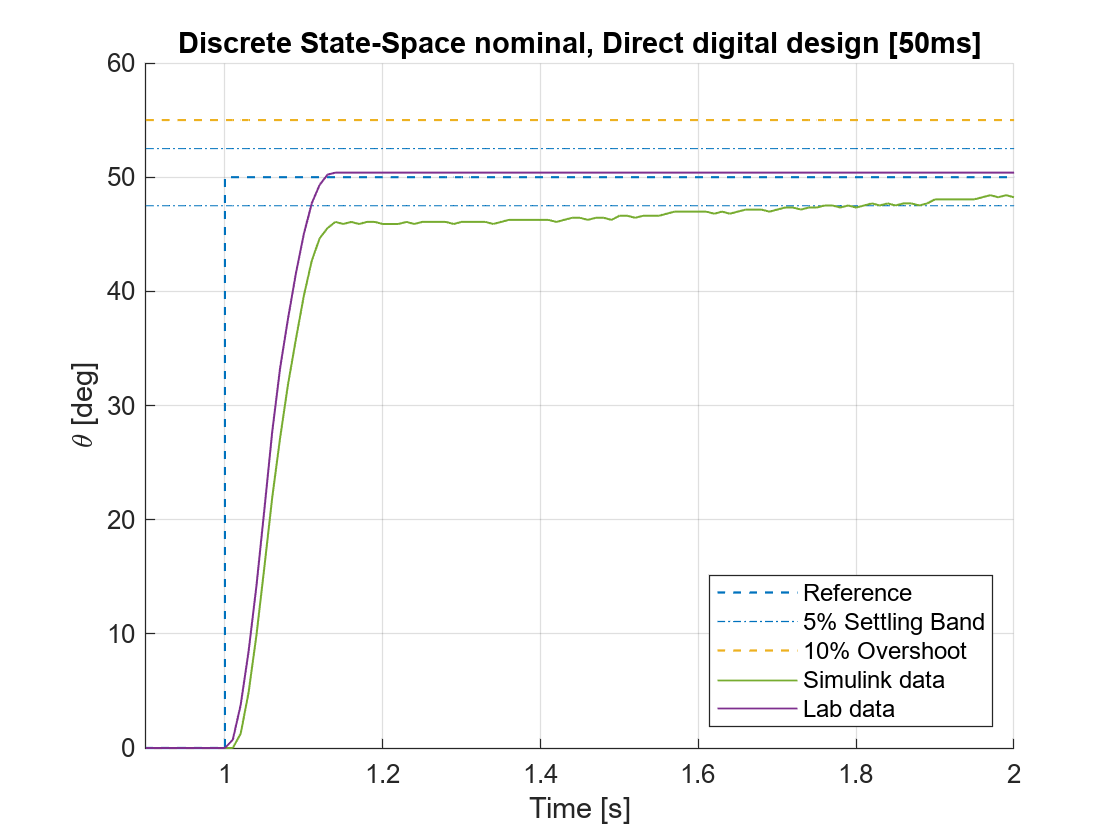

figure
hold on
% Ref
stairs(ss_direct_nominal.T3.thref.time, ss_direct_nominal.T3.thref.signals.values,'--','LineWidth',0.8)
plot(ss_direct_nominal.T3.thref.time-1, ss_direct_nominal.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(ss_direct_nominal.T3.thref.time-1, ss_direct_nominal.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(ss_direct_nominal.T3.thref.time-1, ss_direct_nominal.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_direct_nominal_manual.T3.thl_meas.time, ss_direct_nominal_manual.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(ss_direct_nominal.T3.thl_meas.time, ss_direct_nominal.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space nominal, Direct digital design [50ms]')
axis([0.9 2 0 60])
exportgraphics(gcf,'Figures\10_SS_direct_nominal\50.pdf','ContentType','vector')

#### 1ms, 10ms, 50ms direct design with robust (both lab data and simulink) 

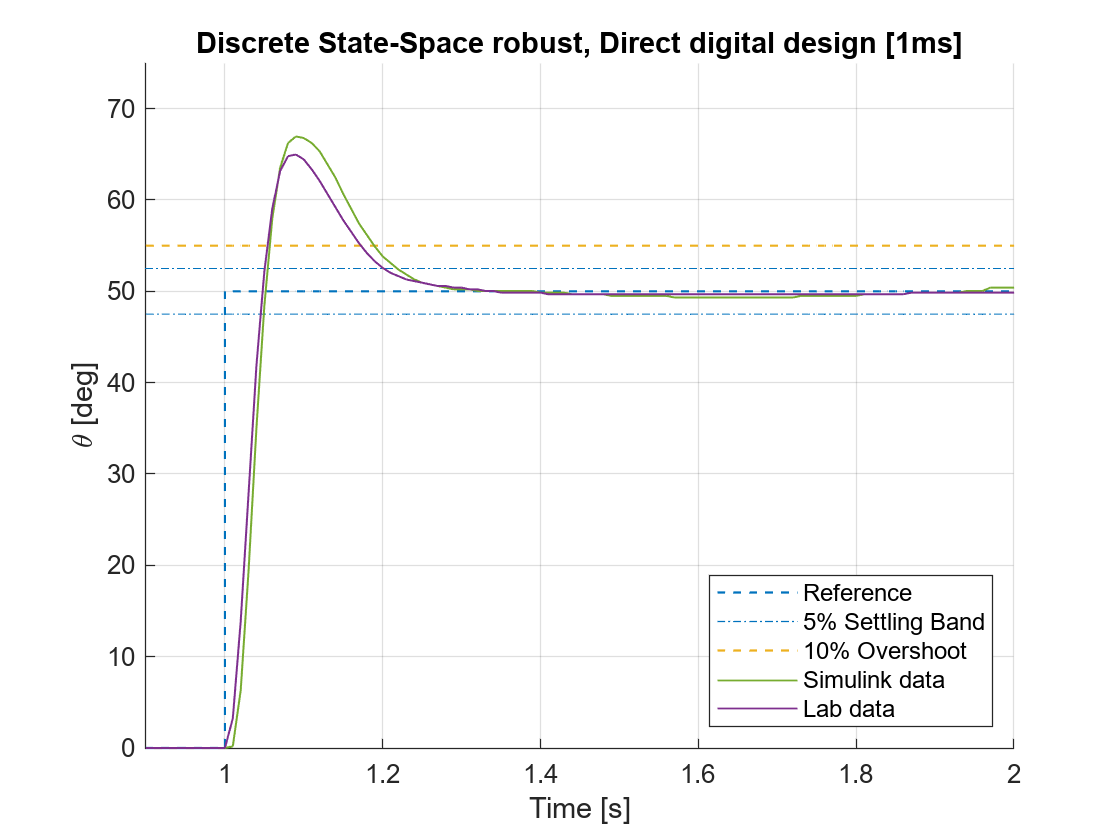


load("LAB_Results\R10_ss_direct_robust.mat")

figure
hold on
% Ref
stairs(ss_direct_robust.T1.thref.time, ss_direct_robust.T1.thref.signals.values,'--','LineWidth',0.8)
plot(ss_direct_robust.T1.thref.time-1, ss_direct_robust.T1.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(ss_direct_robust.T1.thref.time-1, ss_direct_robust.T1.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(ss_direct_robust.T1.thref.time-1, ss_direct_robust.T1.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_direct_robust_manual.T1.thl_meas.time, ss_direct_robust_manual.T1.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(ss_direct_robust.T1.thl_meas.time, ss_direct_robust.T1.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Direct digital design [1ms]')
axis([0.9 2 0 75])
exportgraphics(gcf,'Figures\11_SS_direct_robust\01.pdf','ContentType','vector')

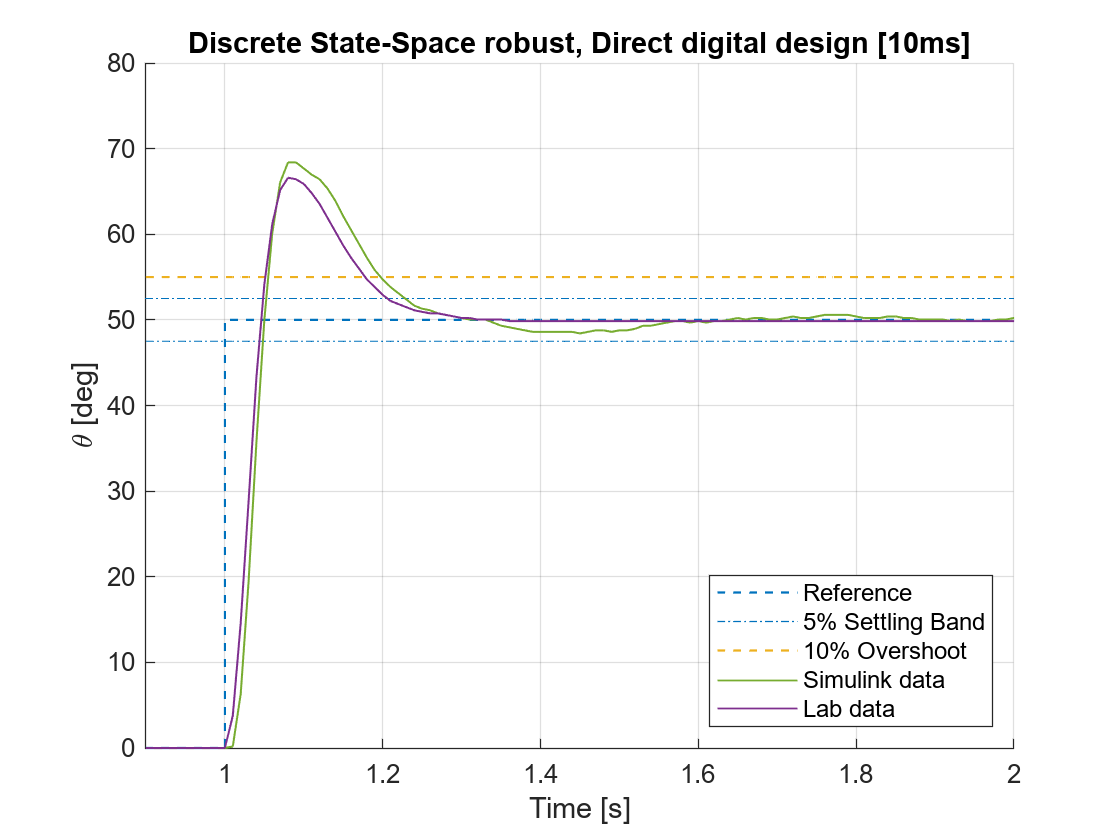

figure
hold on
% Ref
stairs(ss_direct_robust.T2.thref.time, ss_direct_robust.T2.thref.signals.values,'--','LineWidth',0.8)
plot(ss_direct_robust.T2.thref.time-1, ss_direct_robust.T2.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(ss_direct_robust.T2.thref.time-1, ss_direct_robust.T2.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(ss_direct_robust.T2.thref.time-1, ss_direct_robust.T2.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_direct_robust_manual.T2.thl_meas.time, ss_direct_robust_manual.T2.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(ss_direct_robust.T2.thl_meas.time, ss_direct_robust.T2.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Direct digital design [10ms]')
axis([0.9 2 0 80])
exportgraphics(gcf,'Figures\11_SS_direct_robust\10.pdf','ContentType','vector')

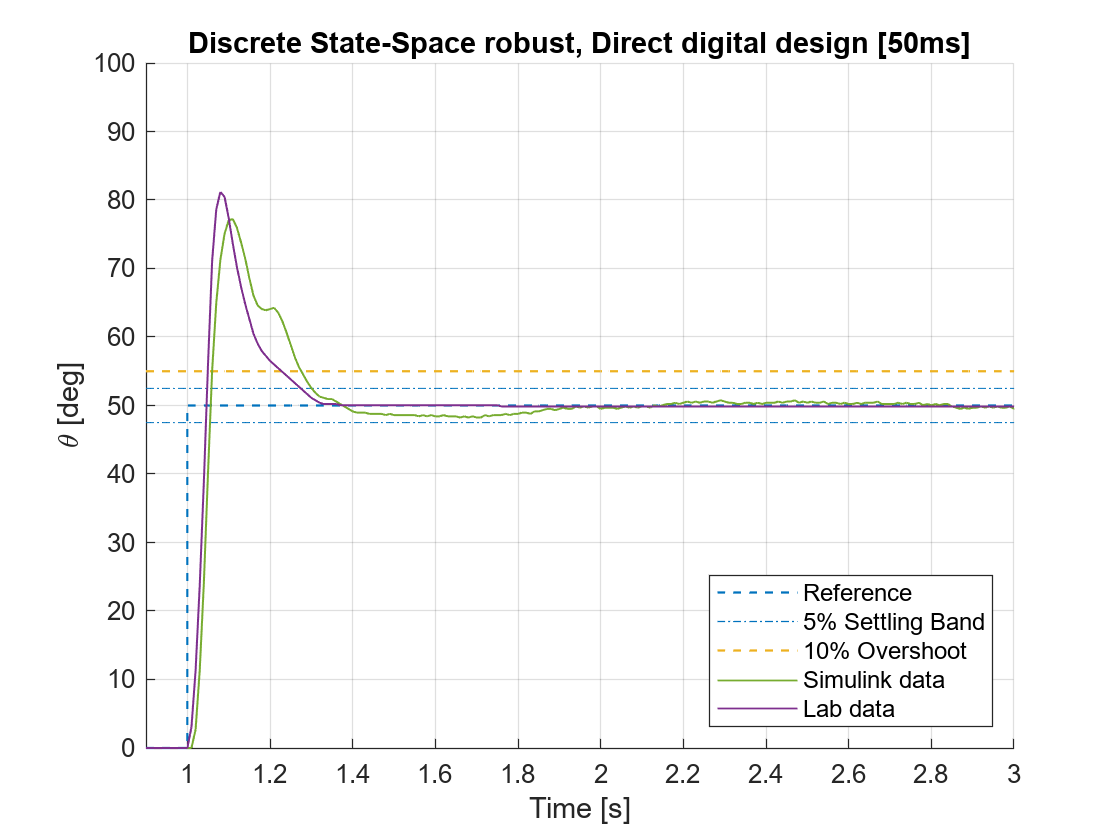

figure
hold on
% Ref
stairs(ss_direct_robust.T3.thref.time, ss_direct_robust.T3.thref.signals.values,'--','LineWidth',0.8)
plot(ss_direct_robust.T3.thref.time-1, ss_direct_robust.T3.thref.signals.values*1.05,'-.','Color',"#0072BD")
plot(ss_direct_robust.T3.thref.time-1, ss_direct_robust.T3.thref.signals.values*0.95,'-.','Color',"#0072BD")
plot(ss_direct_robust.T3.thref.time-1, ss_direct_robust.T3.thref.signals.values*1.1,'--','Color',"#EDB120",'LineWidth',0.8)

% Data
plot(ss_direct_robust_manual.T3.thl_meas.time, ss_direct_robust_manual.T3.thl_meas.signals.values,'LineWidth',0.7, 'Color', '#77AC30')
plot(ss_direct_robust.T3.thl_meas.time, ss_direct_robust.T3.thl_meas.signals.values,'LineWidth',0.7,'Color',	"#7E2F8E")
% Legend
legend('Reference','5% Settling Band','','10% Overshoot','Simulink data','Lab data','Location','southeast')
grid on;
xlabel('Time [s]')
ylabel('\theta [deg]')
title('Discrete State-Space robust, Direct digital design [50ms]')
axis([0.9 3 0 100])
exportgraphics(gcf,'Figures\11_SS_direct_robust\50.pdf','ContentType','vector')